resnet18();

pretrainedURL = 'https://www.mathworks.com/supportfiles/vision/data/deeplabv3plusResnet18CamVid.mat';
pretrainedFolder = fullfile(tempdir,'pretrainedNetwork');
pretrainedNetwork = fullfile(pretrainedFolder,'deeplabv3plusResnet18CamVid.mat'); 
if ~exist(pretrainedNetwork,'file')
    mkdir(pretrainedFolder);
    disp('Downloading pretrained network (58 MB)...');
    websave(pretrainedNetwork,pretrainedURL);
end

imageURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/files/701_StillsRaw_full.zip';
labelURL = 'http://web4.cs.ucl.ac.uk/staff/g.brostow/MotionSegRecData/data/LabeledApproved_full.zip';
 
outputFolder = fullfile(tempdir,'CamVid'); 
labelsZip = fullfile(outputFolder,'labels.zip');
imagesZip = fullfile(outputFolder,'images.zip');

if ~exist(labelsZip, 'file') || ~exist(imagesZip,'file')   
    mkdir(outputFolder)
       
    disp('Downloading 16 MB CamVid dataset labels...'); 
    websave(labelsZip, labelURL);
    unzip(labelsZip, fullfile(outputFolder,'labels'));
    
    disp('Downloading 557 MB CamVid dataset images...');  
    websave(imagesZip, imageURL);       
    unzip(imagesZip, fullfile(outputFolder,'images'));    
end

imgDir = fullfile(outputFolder,'images','701_StillsRaw_full');
imds = imageDatastore(imgDir);

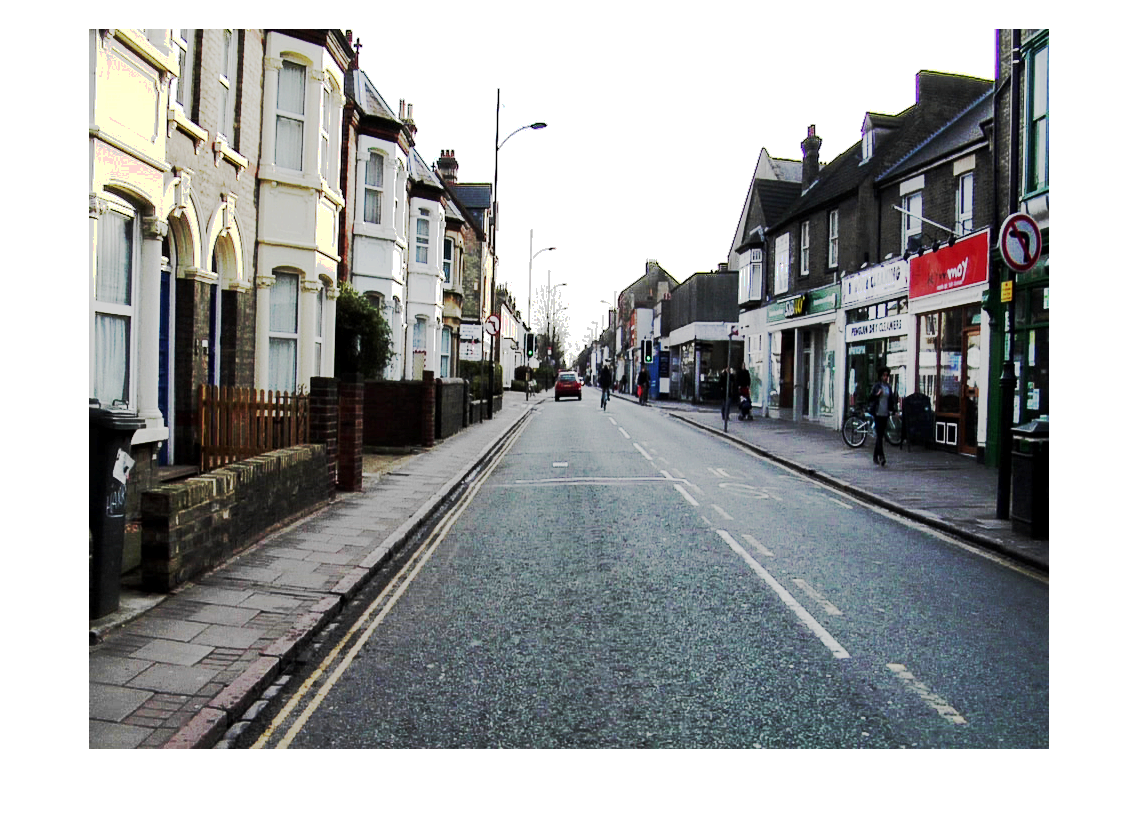

I = readimage(imds,559);
I = histeq(I);
imshow(I)

classes = [
    "Sky"
    "Building"
    "Pole"
    "Road"
    "Pavement"
    "Tree"
    "SignSymbol"
    "Fence"
    "Car"
    "Pedestrian"
    "Bicyclist"
    ];

labelIDs = camvidPixelLabelIDs();
labelDir = fullfile(outputFolder,'labels');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs);

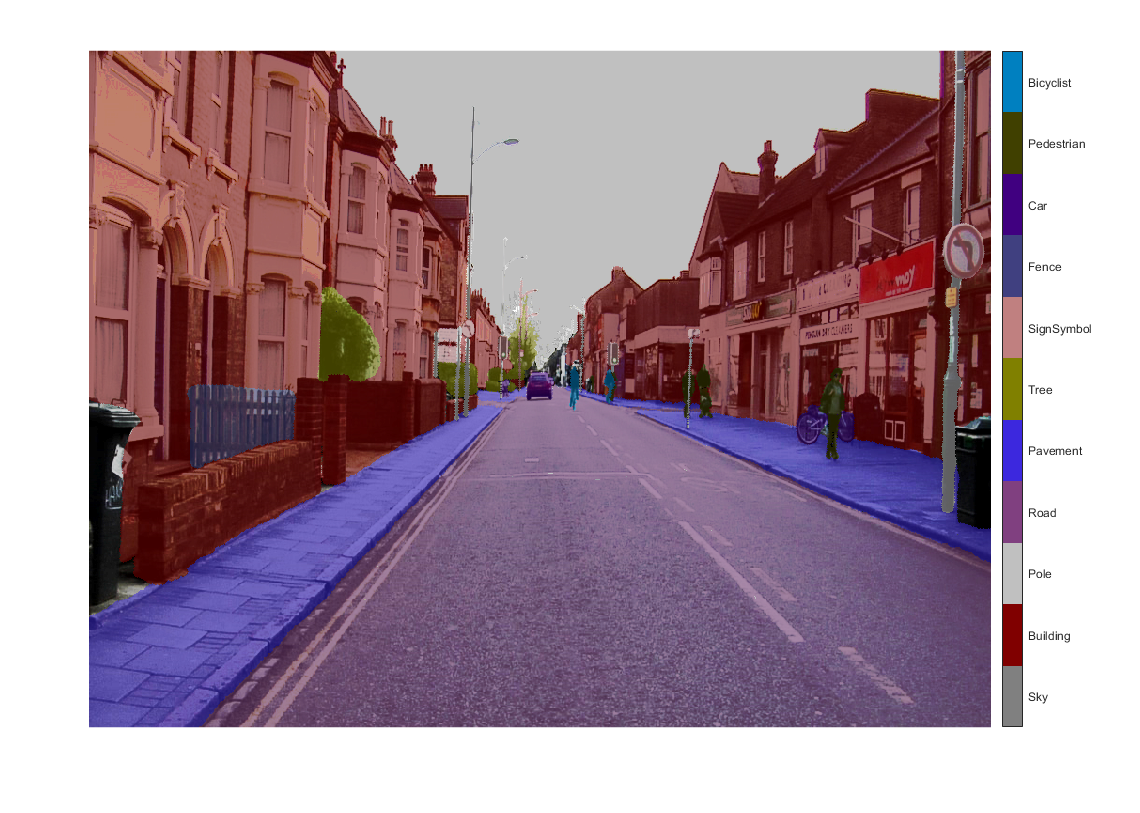

C = readimage(pxds,559);
cmap = camvidColorMap;
B = labeloverlay(I,C,'ColorMap',cmap);
imshow(B)
pixelLabelColorbar(cmap,classes);

tbl = countEachLabel(pxds)

tbl = 11×3 table
         Name         PixelCount    ImagePixelCount
    ______________    __________    _______________
    {'Sky'       }    7.6801e+07      4.8315e+08   
    {'Building'  }    1.1737e+08      4.8315e+08   
    {'Pole'      }    4.7987e+06      4.8315e+08   
    {'Road'      }    1.4054e+08      4.8453e+08   
    {'Pavement'  }    3.3614e+07      4.7209e+08   
    {'Tree'      }    5.4259e+07       4.479e+08   
    {'SignSymbol'}    5.2242e+06      4.6863e+08   
    {'Fence'     }    6.9211e+06       2.516e+08   
    {'Car'       }    2.4437e+07      4.8315e+08   
    {'Pedestrian'}    3.4029e+06      4.4444e+08   
    {'Bicyclist' }    2.5912e+06      2.6196e+08   

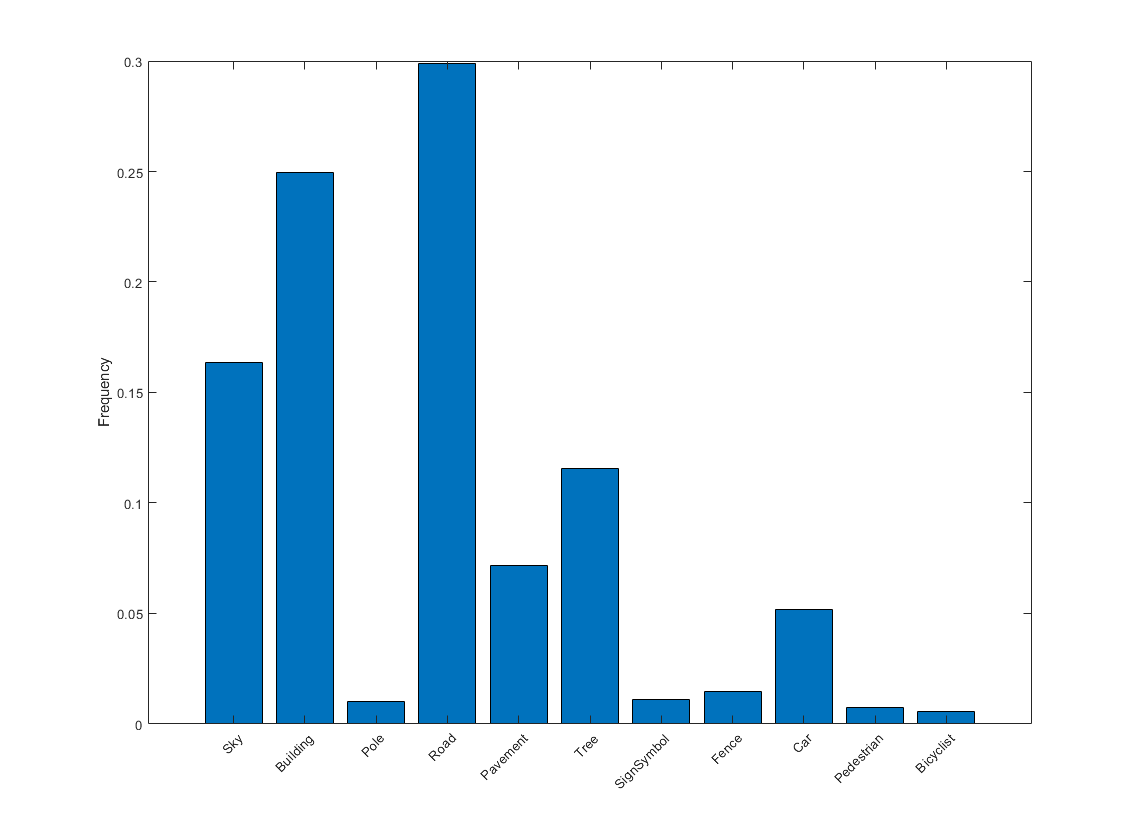


frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds);
numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 421

numValImages = numel(imdsVal.Files)

numValImages = 140

numTestingImages = numel(imdsTest.Files)

numTestingImages = 140

imageSize = [720 960 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
lgraph = deeplabv3plusLayers(imageSize, numClasses, "resnet18");

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.3182
    0.2082
    5.0924
    0.1744
    0.7103
    0.4175
    4.5371
    1.8386
    1.0000
    6.6059


pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

% Define validation data.
pximdsVal = pixelLabelImageDatastore(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',pximdsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',2, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', pwd, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4);

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

pximds = pixelLabelImageDatastore(imdsTrain,pxdsTrain, ...
    'DataAugmentation',augmenter);

Training on single GPU.
Initializing input data normalization.


|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:03:23 |        6.63% |        9.59% |       2.6936 |       2.6073 |          0.0010 |


|       1 |           2 |       00:03:46 |        8.22% |              |       2.6647 |              |          0.0010 |


|       1 |           4 |       00:04:09 |       21.57% |              |       2.1134 |              |          0.0010 |


|       1 |           6 |       00:04:32 |       43.95% |              |       1.7597 |              |          0.0010 |


|       1 |           8 |       00:04:56 |       39.86% |              |       1.7678 |              |          0.0010 |


|       1 |          10 |       00:05:18 |       56.57% |              |       1.3590 |              |          0.0010 |


|       1 |          12 |       00:05:42 |       60.41% |              |       1.7352 |              |          0.0010 |


|       1 |          14 |       00:06:05 |       57.15% |              |       1.6849 |              |          0.0010 |


|       1 |          16 |       00:06:29 |       53.89% |              |       1.3147 |              |          0.0010 |


|       1 |          18 |       00:06:52 |       61.68% |              |       1.4771 |              |          0.0010 |


|       1 |          20 |       00:07:16 |       59.94% |              |       1.1917 |              |          0.0010 |


|       1 |          22 |       00:07:40 |       73.28% |              |       0.9926 |              |          0.0010 |


|       1 |          24 |       00:08:04 |       70.27% |              |       0.9662 |              |          0.0010 |


|       1 |          26 |       00:08:28 |       73.57% |              |       0.8661 |              |          0.0010 |


|       1 |          28 |       00:08:51 |       59.46% |              |       1.5224 |              |          0.0010 |


|       1 |          30 |       00:09:16 |       75.87% |              |       0.8693 |              |          0.0010 |


|       1 |          32 |       00:09:40 |       59.48% |              |       1.2340 |              |          0.0010 |


|       1 |          34 |       00:10:07 |       58.16% |              |       1.0250 |              |          0.0010 |


|       1 |          36 |       00:10:31 |       59.89% |              |       1.3700 |              |          0.0010 |


|       1 |          38 |       00:10:55 |       70.90% |              |       1.0852 |              |          0.0010 |


|       1 |          40 |       00:11:19 |       71.92% |              |       0.9671 |              |          0.0010 |


|       1 |          42 |       00:11:43 |       74.90% |              |       1.0277 |              |          0.0010 |


|       1 |          44 |       00:12:07 |       75.23% |              |       0.8800 |              |          0.0010 |


|       1 |          46 |       00:12:31 |       75.87% |              |       0.7814 |              |          0.0010 |


|       1 |          48 |       00:12:54 |       75.30% |              |       0.8716 |              |          0.0010 |


|       1 |          50 |       00:16:01 |       70.02% |       69.58% |       0.8052 |       0.8084 |          0.0010 |


|       1 |          52 |       00:16:36 |       62.02% |              |       0.9068 |              |          0.0010 |


|       1 |          54 |       00:16:59 |       72.46% |              |       0.5914 |              |          0.0010 |


|       1 |          56 |       00:17:23 |       67.52% |              |       0.9111 |              |          0.0010 |


|       1 |          58 |       00:17:47 |       70.46% |              |       0.8381 |              |          0.0010 |


|       1 |          60 |       00:18:11 |       69.65% |              |       1.1278 |              |          0.0010 |


|       1 |          62 |       00:18:35 |       73.30% |              |       0.8739 |              |          0.0010 |


|       1 |          64 |       00:18:59 |       76.42% |              |       0.6865 |              |          0.0010 |


|       1 |          66 |       00:19:23 |       78.61% |              |       0.6649 |              |          0.0010 |


|       1 |          68 |       00:19:47 |       73.92% |              |       0.7597 |              |          0.0010 |


|       1 |          70 |       00:20:11 |       72.66% |              |       0.8641 |              |          0.0010 |


|       1 |          72 |       00:20:35 |       71.05% |              |       0.7932 |              |          0.0010 |


|       1 |          74 |       00:20:59 |       69.09% |              |       1.0298 |              |          0.0010 |


|       1 |          76 |       00:21:23 |       76.12% |              |       0.6053 |              |          0.0010 |


|       1 |          78 |       00:21:46 |       74.31% |              |       0.7495 |              |          0.0010 |


|       1 |          80 |       00:22:10 |       76.18% |              |       0.6206 |              |          0.0010 |


|       1 |          82 |       00:22:36 |       63.13% |              |       0.9006 |              |          0.0010 |


|       1 |          84 |       00:22:58 |       60.60% |              |       0.9392 |              |          0.0010 |


|       1 |          86 |       00:23:22 |       77.36% |              |       0.6271 |              |          0.0010 |


|       1 |          88 |       00:23:46 |       84.19% |              |       0.5300 |              |          0.0010 |


|       1 |          90 |       00:24:11 |       76.59% |              |       0.9344 |              |          0.0010 |


|       1 |          92 |       00:24:35 |       82.77% |              |       0.4541 |              |          0.0010 |


|       1 |          94 |       00:24:59 |       78.02% |              |       0.5388 |              |          0.0010 |


|       1 |          96 |       00:25:23 |       67.80% |              |       0.6456 |              |          0.0010 |


|       1 |          98 |       00:25:47 |       79.58% |              |       0.5198 |              |          0.0010 |


|       1 |         100 |       00:29:12 |       77.67% |       77.53% |       0.8198 |       0.6429 |          0.0010 |


|       1 |         102 |       00:29:57 |       80.77% |              |       0.5366 |              |          0.0010 |


|       1 |         104 |       00:30:24 |       83.97% |              |       0.5115 |              |          0.0010 |


|       1 |         106 |       00:30:48 |       80.59% |              |       0.4816 |              |          0.0010 |


|       1 |         108 |       00:31:13 |       68.88% |              |       0.9184 |              |          0.0010 |


|       1 |         110 |       00:31:37 |       72.58% |              |       0.5356 |              |          0.0010 |


|       1 |         112 |       00:32:01 |       81.86% |              |       0.5077 |              |          0.0010 |


|       1 |         114 |       00:32:25 |       73.04% |              |       0.5869 |              |          0.0010 |


|       1 |         116 |       00:32:49 |       74.97% |              |       0.8531 |              |          0.0010 |


|       1 |         118 |       00:33:14 |       79.34% |              |       0.6631 |              |          0.0010 |


|       1 |         120 |       00:33:36 |       61.21% |              |       1.1611 |              |          0.0010 |


|       1 |         122 |       00:34:00 |       74.01% |              |       0.8850 |              |          0.0010 |


|       1 |         124 |       00:34:25 |       79.40% |              |       0.4977 |              |          0.0010 |


|       1 |         126 |       00:34:49 |       81.77% |              |       0.5808 |              |          0.0010 |


|       1 |         128 |       00:35:13 |       69.64% |              |       1.0059 |              |          0.0010 |


|       1 |         130 |       00:35:37 |       79.95% |              |       0.6818 |              |          0.0010 |


|       1 |         132 |       00:36:00 |       81.64% |              |       0.7745 |              |          0.0010 |


|       1 |         134 |       00:36:24 |       76.93% |              |       0.6075 |              |          0.0010 |


|       1 |         136 |       00:36:47 |       84.47% |              |       0.4347 |              |          0.0010 |


|       1 |         138 |       00:37:11 |       79.01% |              |       0.5829 |              |          0.0010 |


|       1 |         140 |       00:37:35 |       72.78% |              |       0.7014 |              |          0.0010 |


|       1 |         142 |       00:37:59 |       79.06% |              |       0.5856 |              |          0.0010 |


|       1 |         144 |       00:38:23 |       77.01% |              |       0.6635 |              |          0.0010 |


|       1 |         146 |       00:38:47 |       78.92% |              |       0.7537 |              |          0.0010 |


|       1 |         148 |       00:39:12 |       77.43% |              |       0.5306 |              |          0.0010 |


|       1 |         150 |       00:42:23 |       76.30% |       78.98% |       0.7456 |       0.5946 |          0.0010 |


|       1 |         152 |       00:42:58 |       80.38% |              |       0.5882 |              |          0.0010 |


|       1 |         154 |       00:43:21 |       84.34% |              |       0.4294 |              |          0.0010 |


|       1 |         156 |       00:43:45 |       79.69% |              |       0.5858 |              |          0.0010 |


|       1 |         158 |       00:44:09 |       76.07% |              |       0.6775 |              |          0.0010 |


|       1 |         160 |       00:44:34 |       80.78% |              |       0.6774 |              |          0.0010 |


|       1 |         162 |       00:45:00 |       75.78% |              |       0.5840 |              |          0.0010 |


|       1 |         164 |       00:45:24 |       81.24% |              |       0.4528 |              |          0.0010 |


|       1 |         166 |       00:45:49 |       76.83% |              |       0.5057 |              |          0.0010 |


|       1 |         168 |       00:46:13 |       78.44% |              |       0.5590 |              |          0.0010 |


|       1 |         170 |       00:46:37 |       79.95% |              |       0.6406 |              |          0.0010 |


|       1 |         172 |       00:47:01 |       80.08% |              |       0.7938 |              |          0.0010 |


|       1 |         174 |       00:47:25 |       77.31% |              |       0.7588 |              |          0.0010 |


|       1 |         176 |       00:47:49 |       78.93% |              |       0.5697 |              |          0.0010 |


|       1 |         178 |       00:48:13 |       76.60% |              |       0.6701 |              |          0.0010 |


|       1 |         180 |       00:48:37 |       83.24% |              |       0.4848 |              |          0.0010 |


|       1 |         182 |       00:49:02 |       79.83% |              |       0.6015 |              |          0.0010 |


|       1 |         184 |       00:49:26 |       83.53% |              |       0.5513 |              |          0.0010 |


|       1 |         186 |       00:49:49 |       86.05% |              |       0.4236 |              |          0.0010 |


|       1 |         188 |       00:50:13 |       83.22% |              |       0.4955 |              |          0.0010 |


|       1 |         190 |       00:50:37 |       76.51% |              |       0.6273 |              |          0.0010 |


|       1 |         192 |       00:51:01 |       83.71% |              |       0.4566 |              |          0.0010 |


|       1 |         194 |       00:51:24 |       75.14% |              |       0.5043 |              |          0.0010 |


|       1 |         196 |       00:51:48 |       76.45% |              |       0.7088 |              |          0.0010 |


|       1 |         198 |       00:52:12 |       75.98% |              |       0.8729 |              |          0.0010 |


|       1 |         200 |       00:55:19 |       75.23% |       80.92% |       0.7325 |       0.5557 |          0.0010 |


|       1 |         202 |       00:56:03 |       79.63% |              |       0.5469 |              |          0.0010 |


|       1 |         204 |       00:56:27 |       78.23% |              |       0.5862 |              |          0.0010 |


|       1 |         206 |       00:56:51 |       64.92% |              |       0.8838 |              |          0.0010 |


|       1 |         208 |       00:57:15 |       76.62% |              |       0.5806 |              |          0.0010 |


|       1 |         210 |       00:57:39 |       78.79% |              |       0.4435 |              |          0.0010 |


|       2 |         212 |       00:58:08 |       77.85% |              |       0.5185 |              |          0.0010 |


|       2 |         214 |       00:58:32 |       74.83% |              |       0.6834 |              |          0.0010 |


|       2 |         216 |       00:58:56 |       74.86% |              |       0.9218 |              |          0.0010 |


|       2 |         218 |       00:59:20 |       83.25% |              |       0.3779 |              |          0.0010 |


|       2 |         220 |       00:59:44 |       81.99% |              |       0.5006 |              |          0.0010 |


|       2 |         222 |       01:00:08 |       76.28% |              |       0.5333 |              |          0.0010 |


|       2 |         224 |       01:00:32 |       75.82% |              |       0.5633 |              |          0.0010 |


|       2 |         226 |       01:00:56 |       78.28% |              |       0.6825 |              |          0.0010 |


|       2 |         228 |       01:01:19 |       88.42% |              |       0.3066 |              |          0.0010 |


|       2 |         230 |       01:01:44 |       82.83% |              |       0.3874 |              |          0.0010 |


|       2 |         232 |       01:02:08 |       86.30% |              |       0.3493 |              |          0.0010 |


|       2 |         234 |       01:02:31 |       85.80% |              |       0.5090 |              |          0.0010 |


|       2 |         236 |       01:02:55 |       80.93% |              |       0.6799 |              |          0.0010 |


|       2 |         238 |       01:03:19 |       82.13% |              |       0.4499 |              |          0.0010 |


|       2 |         240 |       01:03:43 |       74.41% |              |       0.5860 |              |          0.0010 |


|       2 |         242 |       01:04:08 |       82.47% |              |       0.4021 |              |          0.0010 |


|       2 |         244 |       01:04:32 |       81.41% |              |       0.4307 |              |          0.0010 |


|       2 |         246 |       01:04:56 |       83.19% |              |       0.6002 |              |          0.0010 |


|       2 |         248 |       01:05:20 |       85.69% |              |       0.5169 |              |          0.0010 |


|       2 |         250 |       01:08:32 |       82.49% |       81.87% |       0.5214 |       0.5058 |          0.0010 |


|       2 |         252 |       01:09:06 |       78.71% |              |       0.4939 |              |          0.0010 |


|       2 |         254 |       01:09:30 |       83.65% |              |       0.3458 |              |          0.0010 |


|       2 |         256 |       01:09:54 |       83.17% |              |       0.4447 |              |          0.0010 |


|       2 |         258 |       01:10:18 |       84.35% |              |       0.4951 |              |          0.0010 |


|       2 |         260 |       01:10:42 |       83.29% |              |       0.4098 |              |          0.0010 |


|       2 |         262 |       01:11:07 |       75.39% |              |       0.6646 |              |          0.0010 |


|       2 |         264 |       01:11:32 |       79.09% |              |       0.4852 |              |          0.0010 |


|       2 |         266 |       01:11:56 |       78.73% |              |       0.4418 |              |          0.0010 |


|       2 |         268 |       01:12:20 |       84.83% |              |       0.4383 |              |          0.0010 |


|       2 |         270 |       01:12:44 |       87.08% |              |       0.2929 |              |          0.0010 |


|       2 |         272 |       01:13:08 |       80.35% |              |       0.5959 |              |          0.0010 |


|       2 |         274 |       01:13:32 |       78.71% |              |       0.5614 |              |          0.0010 |


|       2 |         276 |       01:13:57 |       79.74% |              |       0.6224 |              |          0.0010 |


|       2 |         278 |       01:14:21 |       82.08% |              |       0.4181 |              |          0.0010 |


|       2 |         280 |       01:14:45 |       79.41% |              |       0.3923 |              |          0.0010 |


|       2 |         282 |       01:15:08 |       78.48% |              |       0.4976 |              |          0.0010 |


|       2 |         284 |       01:15:33 |       79.28% |              |       0.6239 |              |          0.0010 |


|       2 |         286 |       01:15:57 |       84.10% |              |       0.4061 |              |          0.0010 |


|       2 |         288 |       01:16:21 |       83.46% |              |       0.4289 |              |          0.0010 |


|       2 |         290 |       01:16:45 |       83.62% |              |       0.5772 |              |          0.0010 |


|       2 |         292 |       01:17:10 |       84.38% |              |       0.5259 |              |          0.0010 |


|       2 |         294 |       01:17:34 |       68.54% |              |       0.6892 |              |          0.0010 |


|       2 |         296 |       01:17:58 |       86.38% |              |       0.4249 |              |          0.0010 |


|       2 |         298 |       01:18:22 |       80.89% |              |       0.4920 |              |          0.0010 |


|       2 |         300 |       01:21:29 |       82.42% |       83.08% |       0.4128 |       0.4928 |          0.0010 |


|       2 |         302 |       01:22:07 |       86.24% |              |       0.4090 |              |          0.0010 |


|       2 |         304 |       01:22:32 |       81.08% |              |       0.7127 |              |          0.0010 |


|       2 |         306 |       01:22:56 |       77.99% |              |       0.5306 |              |          0.0010 |


|       2 |         308 |       01:23:20 |       82.65% |              |       0.5219 |              |          0.0010 |


|       2 |         310 |       01:23:44 |       80.38% |              |       0.4035 |              |          0.0010 |


|       2 |         312 |       01:24:08 |       83.08% |              |       0.4528 |              |          0.0010 |


|       2 |         314 |       01:24:32 |       82.68% |              |       0.3283 |              |          0.0010 |


|       2 |         316 |       01:24:56 |       75.49% |              |       0.5142 |              |          0.0010 |


|       2 |         318 |       01:25:20 |       78.67% |              |       0.6000 |              |          0.0010 |


|       2 |         320 |       01:25:44 |       85.79% |              |       0.4219 |              |          0.0010 |


|       2 |         322 |       01:26:08 |       80.24% |              |       0.3478 |              |          0.0010 |


|       2 |         324 |       01:26:32 |       79.44% |              |       0.5381 |              |          0.0010 |


|       2 |         326 |       01:26:56 |       78.26% |              |       0.5583 |              |          0.0010 |


|       2 |         328 |       01:27:20 |       86.24% |              |       0.4169 |              |          0.0010 |


|       2 |         330 |       01:27:45 |       83.86% |              |       0.4338 |              |          0.0010 |


|       2 |         332 |       01:28:09 |       74.87% |              |       0.5698 |              |          0.0010 |


|       2 |         334 |       01:28:33 |       79.55% |              |       0.3643 |              |          0.0010 |


|       2 |         336 |       01:28:57 |       84.43% |              |       0.3556 |              |          0.0010 |


|       2 |         338 |       01:29:21 |       79.20% |              |       0.5090 |              |          0.0010 |


|       2 |         340 |       01:29:45 |       82.95% |              |       0.4384 |              |          0.0010 |


|       2 |         342 |       01:30:09 |       82.40% |              |       0.4535 |              |          0.0010 |


|       2 |         344 |       01:30:33 |       85.26% |              |       0.4377 |              |          0.0010 |


|       2 |         346 |       01:30:57 |       82.10% |              |       0.4505 |              |          0.0010 |


|       2 |         348 |       01:31:21 |       77.62% |              |       0.5145 |              |          0.0010 |


|       2 |         350 |       01:34:27 |       79.04% |       82.18% |       0.3923 |       0.4590 |          0.0010 |


|       2 |         352 |       01:35:08 |       84.69% |              |       0.3078 |              |          0.0010 |


|       2 |         354 |       01:35:32 |       82.35% |              |       0.5001 |              |          0.0010 |


|       2 |         356 |       01:35:56 |       84.77% |              |       0.4758 |              |          0.0010 |


|       2 |         358 |       01:36:19 |       85.60% |              |       0.3814 |              |          0.0010 |


|       2 |         360 |       01:36:43 |       78.62% |              |       0.5553 |              |          0.0010 |


|       2 |         362 |       01:37:07 |       81.67% |              |       0.4950 |              |          0.0010 |


|       2 |         364 |       01:37:31 |       87.26% |              |       0.4703 |              |          0.0010 |


|       2 |         366 |       01:37:55 |       77.69% |              |       0.4519 |              |          0.0010 |


|       2 |         368 |       01:38:18 |       80.62% |              |       0.4565 |              |          0.0010 |


|       2 |         370 |       01:38:42 |       84.03% |              |       0.4687 |              |          0.0010 |


|       2 |         372 |       01:39:06 |       80.03% |              |       0.6381 |              |          0.0010 |


|       2 |         374 |       01:39:30 |       83.66% |              |       0.4135 |              |          0.0010 |


|       2 |         376 |       01:39:54 |       85.92% |              |       0.3610 |              |          0.0010 |


|       2 |         378 |       01:40:18 |       82.17% |              |       0.3456 |              |          0.0010 |


|       2 |         380 |       01:40:41 |       78.13% |              |       0.6189 |              |          0.0010 |


|       2 |         382 |       01:41:05 |       79.51% |              |       0.6198 |              |          0.0010 |


|       2 |         384 |       01:41:29 |       85.49% |              |       0.3593 |              |          0.0010 |


|       2 |         386 |       01:41:53 |       86.52% |              |       0.3992 |              |          0.0010 |


|       2 |         388 |       01:42:17 |       81.76% |              |       0.5100 |              |          0.0010 |


|       2 |         390 |       01:42:41 |       75.65% |              |       0.7130 |              |          0.0010 |


|       2 |         392 |       01:43:05 |       81.20% |              |       0.5208 |              |          0.0010 |


|       2 |         394 |       01:43:28 |       83.17% |              |       0.4746 |              |          0.0010 |


|       2 |         396 |       01:43:52 |       74.40% |              |       0.2861 |              |          0.0010 |


|       2 |         398 |       01:44:16 |       81.10% |              |       0.5131 |              |          0.0010 |


|       2 |         400 |       01:47:35 |       82.43% |       81.89% |       0.5388 |       0.4624 |          0.0010 |


|       2 |         402 |       01:48:18 |       85.99% |              |       0.3766 |              |          0.0010 |


|       2 |         404 |       01:48:41 |       82.21% |              |       0.4130 |              |          0.0010 |


|       2 |         406 |       01:49:06 |       83.91% |              |       0.4339 |              |          0.0010 |


|       2 |         408 |       01:49:29 |       73.93% |              |       0.4241 |              |          0.0010 |


|       2 |         410 |       01:49:53 |       77.00% |              |       0.5322 |              |          0.0010 |


|       2 |         412 |       01:50:17 |       84.01% |              |       0.5681 |              |          0.0010 |


|       2 |         414 |       01:50:41 |       86.83% |              |       0.2799 |              |          0.0010 |


|       2 |         416 |       01:51:05 |       87.62% |              |       0.3739 |              |          0.0010 |


|       2 |         418 |       01:51:29 |       80.89% |              |       0.4784 |              |          0.0010 |


|       2 |         420 |       01:51:53 |       82.97% |              |       0.5319 |              |          0.0010 |


|       3 |         422 |       01:52:20 |       84.12% |              |       0.3210 |              |          0.0010 |


|       3 |         424 |       01:52:44 |       82.50% |              |       0.5241 |              |          0.0010 |


|       3 |         426 |       01:53:08 |       80.24% |              |       0.4753 |              |          0.0010 |


|       3 |         428 |       01:53:32 |       79.54% |              |       0.5059 |              |          0.0010 |


|       3 |         430 |       01:53:56 |       86.81% |              |       0.3793 |              |          0.0010 |


|       3 |         432 |       01:54:20 |       82.14% |              |       0.4421 |              |          0.0010 |


|       3 |         434 |       01:54:44 |       87.97% |              |       0.3096 |              |          0.0010 |


|       3 |         436 |       01:55:08 |       82.30% |              |       0.3746 |              |          0.0010 |


|       3 |         438 |       01:55:32 |       82.88% |              |       0.3751 |              |          0.0010 |


|       3 |         440 |       01:55:55 |       83.14% |              |       0.3825 |              |          0.0010 |


|       3 |         442 |       01:56:19 |       80.92% |              |       0.3772 |              |          0.0010 |


|       3 |         444 |       01:56:43 |       90.57% |              |       0.3421 |              |          0.0010 |


|       3 |         446 |       01:57:07 |       86.86% |              |       0.3713 |              |          0.0010 |


|       3 |         448 |       01:57:34 |       84.02% |              |       0.3484 |              |          0.0010 |


|       3 |         450 |       02:01:18 |       85.51% |       83.88% |       0.4652 |       0.4244 |          0.0010 |


|       3 |         452 |       02:01:57 |       80.92% |              |       0.4741 |              |          0.0010 |


|       3 |         454 |       02:02:21 |       85.52% |              |       0.4275 |              |          0.0010 |


|       3 |         456 |       02:02:46 |       79.47% |              |       0.5395 |              |          0.0010 |


|       3 |         458 |       02:03:10 |       86.25% |              |       0.3538 |              |          0.0010 |


|       3 |         460 |       02:03:34 |       82.16% |              |       0.4111 |              |          0.0010 |


|       3 |         462 |       02:03:58 |       81.09% |              |       0.4739 |              |          0.0010 |


|       3 |         464 |       02:04:22 |       87.98% |              |       0.4530 |              |          0.0010 |


|       3 |         466 |       02:04:46 |       84.57% |              |       0.4078 |              |          0.0010 |


|       3 |         468 |       02:05:10 |       81.33% |              |       0.4345 |              |          0.0010 |


|       3 |         470 |       02:05:34 |       85.44% |              |       0.2878 |              |          0.0010 |


|       3 |         472 |       02:05:59 |       81.90% |              |       0.5051 |              |          0.0010 |


|       3 |         474 |       02:06:23 |       81.57% |              |       0.4626 |              |          0.0010 |


|       3 |         476 |       02:06:47 |       85.17% |              |       0.3905 |              |          0.0010 |


|       3 |         478 |       02:07:11 |       84.78% |              |       0.3230 |              |          0.0010 |


|       3 |         480 |       02:07:35 |       81.36% |              |       0.6255 |              |          0.0010 |


|       3 |         482 |       02:07:59 |       86.32% |              |       0.3334 |              |          0.0010 |


|       3 |         484 |       02:08:23 |       81.05% |              |       0.4199 |              |          0.0010 |


|       3 |         486 |       02:08:47 |       85.26% |              |       0.3272 |              |          0.0010 |


|       3 |         488 |       02:09:11 |       82.28% |              |       0.4807 |              |          0.0010 |


|       3 |         490 |       02:09:34 |       80.86% |              |       0.3649 |              |          0.0010 |


|       3 |         492 |       02:09:58 |       84.67% |              |       0.3015 |              |          0.0010 |


|       3 |         494 |       02:10:22 |       83.39% |              |       0.4183 |              |          0.0010 |


|       3 |         496 |       02:10:46 |       87.40% |              |       0.3800 |              |          0.0010 |


|       3 |         498 |       02:11:10 |       83.91% |              |       0.4804 |              |          0.0010 |


|       3 |         500 |       02:15:01 |       82.69% |       85.72% |       0.6063 |       0.4149 |          0.0010 |


|       3 |         502 |       02:15:42 |       86.36% |              |       0.2884 |              |          0.0010 |


|       3 |         504 |       02:16:06 |       88.04% |              |       0.3223 |              |          0.0010 |


|       3 |         506 |       02:16:30 |       87.18% |              |       0.2600 |              |          0.0010 |


|       3 |         508 |       02:16:54 |       87.30% |              |       0.3200 |              |          0.0010 |


|       3 |         510 |       02:17:18 |       82.28% |              |       0.3176 |              |          0.0010 |


|       3 |         512 |       02:17:42 |       82.90% |              |       0.5427 |              |          0.0010 |


|       3 |         514 |       02:18:06 |       79.70% |              |       0.4424 |              |          0.0010 |


|       3 |         516 |       02:18:31 |       85.82% |              |       0.3286 |              |          0.0010 |


|       3 |         518 |       02:18:56 |       88.99% |              |       0.2708 |              |          0.0010 |


|       3 |         520 |       02:19:21 |       82.91% |              |       0.3816 |              |          0.0010 |


|       3 |         522 |       02:19:47 |       87.07% |              |       0.3589 |              |          0.0010 |


|       3 |         524 |       02:20:11 |       85.17% |              |       0.3168 |              |          0.0010 |


|       3 |         526 |       02:20:35 |       78.70% |              |       0.2947 |              |          0.0010 |


|       3 |         528 |       02:20:59 |       83.60% |              |       0.4865 |              |          0.0010 |


|       3 |         530 |       02:21:23 |       83.18% |              |       0.3886 |              |          0.0010 |


|       3 |         532 |       02:21:48 |       85.29% |              |       0.3981 |              |          0.0010 |


|       3 |         534 |       02:22:13 |       89.09% |              |       0.2903 |              |          0.0010 |


|       3 |         536 |       02:22:37 |       82.50% |              |       0.5127 |              |          0.0010 |


|       3 |         538 |       02:23:01 |       83.86% |              |       0.3282 |              |          0.0010 |


|       3 |         540 |       02:23:25 |       86.28% |              |       0.3950 |              |          0.0010 |


|       3 |         542 |       02:23:50 |       82.28% |              |       0.6056 |              |          0.0010 |


|       3 |         544 |       02:24:14 |       86.43% |              |       0.3056 |              |          0.0010 |


|       3 |         546 |       02:24:38 |       89.43% |              |       0.3140 |              |          0.0010 |


|       3 |         548 |       02:25:02 |       84.67% |              |       0.3341 |              |          0.0010 |


|       3 |         550 |       02:28:22 |       86.91% |       85.42% |       0.3208 |       0.4060 |          0.0010 |


|       3 |         552 |       02:29:01 |       88.16% |              |       0.3011 |              |          0.0010 |


|       3 |         554 |       02:29:25 |       84.09% |              |       0.3599 |              |          0.0010 |


|       3 |         556 |       02:29:49 |       84.26% |              |       0.3298 |              |          0.0010 |


|       3 |         558 |       02:30:12 |       87.43% |              |       0.3682 |              |          0.0010 |


|       3 |         560 |       02:30:36 |       88.08% |              |       0.2364 |              |          0.0010 |


|       3 |         562 |       02:31:00 |       81.04% |              |       0.5982 |              |          0.0010 |


|       3 |         564 |       02:31:25 |       72.17% |              |       0.4766 |              |          0.0010 |


|       3 |         566 |       02:31:50 |       82.75% |              |       0.4075 |              |          0.0010 |


|       3 |         568 |       02:32:14 |       66.66% |              |       0.5839 |              |          0.0010 |


|       3 |         570 |       02:32:38 |       81.92% |              |       0.4846 |              |          0.0010 |


|       3 |         572 |       02:33:03 |       85.35% |              |       0.4176 |              |          0.0010 |


|       3 |         574 |       02:33:27 |       74.26% |              |       0.4090 |              |          0.0010 |


|       3 |         576 |       02:33:52 |       77.91% |              |       0.4653 |              |          0.0010 |


|       3 |         578 |       02:34:16 |       84.55% |              |       0.3181 |              |          0.0010 |


|       3 |         580 |       02:34:40 |       83.01% |              |       0.5364 |              |          0.0010 |


|       3 |         582 |       02:35:04 |       82.45% |              |       0.4570 |              |          0.0010 |


|       3 |         584 |       02:35:28 |       89.67% |              |       0.2553 |              |          0.0010 |


|       3 |         586 |       02:35:52 |       84.71% |              |       0.3055 |              |          0.0010 |


|       3 |         588 |       02:36:16 |       83.86% |              |       0.3471 |              |          0.0010 |


|       3 |         590 |       02:36:40 |       84.34% |              |       0.3632 |              |          0.0010 |


|       3 |         592 |       02:37:04 |       89.00% |              |       0.3876 |              |          0.0010 |


|       3 |         594 |       02:37:28 |       80.84% |              |       0.4892 |              |          0.0010 |


|       3 |         596 |       02:37:52 |       80.39% |              |       0.6983 |              |          0.0010 |


|       3 |         598 |       02:38:16 |       86.01% |              |       0.2722 |              |          0.0010 |


|       3 |         600 |       02:41:44 |       88.34% |       85.36% |       0.3518 |       0.4105 |          0.0010 |


|       3 |         602 |       02:42:23 |       86.86% |              |       0.2884 |              |          0.0010 |


|       3 |         604 |       02:42:47 |       83.34% |              |       0.5515 |              |          0.0010 |


|       3 |         606 |       02:43:11 |       81.85% |              |       0.5498 |              |          0.0010 |


|       3 |         608 |       02:43:35 |       87.76% |              |       0.3400 |              |          0.0010 |


|       3 |         610 |       02:43:59 |       82.11% |              |       0.4021 |              |          0.0010 |


|       3 |         612 |       02:44:23 |       84.78% |              |       0.3838 |              |          0.0010 |


|       3 |         614 |       02:44:47 |       82.14% |              |       0.4904 |              |          0.0010 |


|       3 |         616 |       02:45:11 |       83.49% |              |       0.3790 |              |          0.0010 |


|       3 |         618 |       02:45:34 |       85.46% |              |       0.3615 |              |          0.0010 |


|       3 |         620 |       02:45:58 |       84.43% |              |       0.4143 |              |          0.0010 |


|       3 |         622 |       02:46:22 |       84.13% |              |       0.3054 |              |          0.0010 |


|       3 |         624 |       02:46:46 |       87.95% |              |       0.3191 |              |          0.0010 |


|       3 |         626 |       02:47:10 |       84.37% |              |       0.3698 |              |          0.0010 |


|       3 |         628 |       02:47:33 |       89.83% |              |       0.2031 |              |          0.0010 |


|       3 |         630 |       02:47:57 |       86.61% |              |       0.3405 |              |          0.0010 |


|       4 |         632 |       02:48:25 |       81.15% |              |       0.5378 |              |          0.0010 |


|       4 |         634 |       02:48:49 |       85.92% |              |       0.3906 |              |          0.0010 |


|       4 |         636 |       02:49:12 |       83.41% |              |       0.3611 |              |          0.0010 |


|       4 |         638 |       02:49:36 |       83.23% |              |       0.3641 |              |          0.0010 |


|       4 |         640 |       02:50:00 |       86.52% |              |       0.3626 |              |          0.0010 |


|       4 |         642 |       02:50:24 |       84.41% |              |       0.3302 |              |          0.0010 |


|       4 |         644 |       02:50:48 |       85.10% |              |       0.2958 |              |          0.0010 |


|       4 |         646 |       02:51:12 |       79.89% |              |       0.3326 |              |          0.0010 |


|       4 |         648 |       02:51:36 |       86.01% |              |       0.4724 |              |          0.0010 |


|       4 |         650 |       02:54:46 |       79.65% |       84.70% |       0.4843 |       0.3994 |          0.0010 |


|       4 |         652 |       02:55:29 |       80.31% |              |       0.3815 |              |          0.0010 |


|       4 |         654 |       02:55:53 |       82.21% |              |       0.2793 |              |          0.0010 |


|       4 |         656 |       02:56:17 |       84.42% |              |       0.3104 |              |          0.0010 |


|       4 |         658 |       02:56:41 |       87.63% |              |       0.3628 |              |          0.0010 |


|       4 |         660 |       02:57:05 |       81.72% |              |       0.3023 |              |          0.0010 |


|       4 |         662 |       02:57:28 |       88.04% |              |       0.3398 |              |          0.0010 |


|       4 |         664 |       02:57:52 |       86.04% |              |       0.3423 |              |          0.0010 |


|       4 |         666 |       02:58:16 |       84.08% |              |       0.3490 |              |          0.0010 |


|       4 |         668 |       02:58:40 |       82.37% |              |       0.4350 |              |          0.0010 |


|       4 |         670 |       02:59:04 |       84.21% |              |       0.3662 |              |          0.0010 |


|       4 |         672 |       02:59:28 |       82.66% |              |       0.3585 |              |          0.0010 |


|       4 |         674 |       02:59:52 |       82.79% |              |       0.3554 |              |          0.0010 |


|       4 |         676 |       03:00:16 |       83.52% |              |       0.4223 |              |          0.0010 |


|       4 |         678 |       03:00:40 |       89.21% |              |       0.2618 |              |          0.0010 |


|       4 |         680 |       03:01:03 |       86.11% |              |       0.2651 |              |          0.0010 |


|       4 |         682 |       03:01:27 |       84.62% |              |       0.4631 |              |          0.0010 |


|       4 |         684 |       03:01:51 |       88.65% |              |       0.2304 |              |          0.0010 |


|       4 |         686 |       03:02:15 |       84.65% |              |       0.3763 |              |          0.0010 |


|       4 |         688 |       03:02:39 |       86.34% |              |       0.3791 |              |          0.0010 |


|       4 |         690 |       03:03:03 |       81.91% |              |       0.3174 |              |          0.0010 |


|       4 |         692 |       03:03:27 |       83.94% |              |       0.4291 |              |          0.0010 |


|       4 |         694 |       03:03:51 |       87.39% |              |       0.2928 |              |          0.0010 |


|       4 |         696 |       03:04:15 |       82.06% |              |       0.3702 |              |          0.0010 |


|       4 |         698 |       03:04:39 |       85.20% |              |       0.2914 |              |          0.0010 |


|       4 |         700 |       03:07:51 |       85.18% |       86.43% |       0.4384 |       0.3784 |          0.0010 |


|       4 |         702 |       03:08:35 |       88.52% |              |       0.2853 |              |          0.0010 |


|       4 |         704 |       03:09:00 |       85.76% |              |       0.2724 |              |          0.0010 |


|       4 |         706 |       03:09:24 |       86.69% |              |       0.3750 |              |          0.0010 |


|       4 |         708 |       03:09:48 |       81.34% |              |       0.3623 |              |          0.0010 |


|       4 |         710 |       03:10:12 |       88.10% |              |       0.2441 |              |          0.0010 |


|       4 |         712 |       03:10:36 |       81.76% |              |       0.3852 |              |          0.0010 |


|       4 |         714 |       03:10:59 |       86.06% |              |       0.3828 |              |          0.0010 |


|       4 |         716 |       03:11:23 |       83.37% |              |       0.4155 |              |          0.0010 |


|       4 |         718 |       03:11:47 |       85.04% |              |       0.4027 |              |          0.0010 |


|       4 |         720 |       03:12:11 |       83.24% |              |       0.4743 |              |          0.0010 |


|       4 |         722 |       03:12:35 |       82.80% |              |       0.4339 |              |          0.0010 |


|       4 |         724 |       03:12:59 |       90.78% |              |       0.3750 |              |          0.0010 |


|       4 |         726 |       03:13:23 |       83.96% |              |       0.3191 |              |          0.0010 |


|       4 |         728 |       03:13:47 |       81.24% |              |       0.4577 |              |          0.0010 |


|       4 |         730 |       03:14:11 |       81.80% |              |       0.4333 |              |          0.0010 |


|       4 |         732 |       03:14:35 |       88.41% |              |       0.2281 |              |          0.0010 |


|       4 |         734 |       03:14:59 |       82.62% |              |       0.3679 |              |          0.0010 |


|       4 |         736 |       03:15:23 |       83.60% |              |       0.3598 |              |          0.0010 |


|       4 |         738 |       03:15:47 |       90.14% |              |       0.3279 |              |          0.0010 |


|       4 |         740 |       03:16:11 |       87.59% |              |       0.3623 |              |          0.0010 |


|       4 |         742 |       03:16:35 |       88.35% |              |       0.3415 |              |          0.0010 |


|       4 |         744 |       03:16:59 |       87.14% |              |       0.3063 |              |          0.0010 |


|       4 |         746 |       03:17:22 |       90.47% |              |       0.3460 |              |          0.0010 |


|       4 |         748 |       03:17:46 |       85.80% |              |       0.2299 |              |          0.0010 |


|       4 |         750 |       03:20:59 |       83.00% |       84.79% |       0.5080 |       0.3814 |          0.0010 |


|       4 |         752 |       03:21:39 |       84.47% |              |       0.2969 |              |          0.0010 |


|       4 |         754 |       03:22:03 |       78.35% |              |       0.5067 |              |          0.0010 |


|       4 |         756 |       03:22:27 |       84.47% |              |       0.3527 |              |          0.0010 |


|       4 |         758 |       03:22:51 |       85.02% |              |       0.2764 |              |          0.0010 |


|       4 |         760 |       03:23:15 |       89.94% |              |       0.2035 |              |          0.0010 |


|       4 |         762 |       03:23:39 |       85.83% |              |       0.3806 |              |          0.0010 |


|       4 |         764 |       03:24:03 |       82.56% |              |       0.3069 |              |          0.0010 |


|       4 |         766 |       03:24:27 |       83.22% |              |       0.3711 |              |          0.0010 |


|       4 |         768 |       03:24:51 |       84.65% |              |       0.3776 |              |          0.0010 |


|       4 |         770 |       03:25:15 |       86.02% |              |       0.4335 |              |          0.0010 |


|       4 |         772 |       03:25:39 |       81.84% |              |       0.4361 |              |          0.0010 |


|       4 |         774 |       03:26:03 |       88.45% |              |       0.1886 |              |          0.0010 |


|       4 |         776 |       03:26:27 |       86.83% |              |       0.2920 |              |          0.0010 |


|       4 |         778 |       03:26:51 |       84.78% |              |       0.2909 |              |          0.0010 |


|       4 |         780 |       03:27:15 |       85.33% |              |       0.4522 |              |          0.0010 |


|       4 |         782 |       03:27:39 |       90.49% |              |       0.2625 |              |          0.0010 |


|       4 |         784 |       03:28:03 |       86.03% |              |       0.4126 |              |          0.0010 |


|       4 |         786 |       03:28:26 |       90.12% |              |       0.2602 |              |          0.0010 |


|       4 |         788 |       03:28:50 |       90.14% |              |       0.1701 |              |          0.0010 |


|       4 |         790 |       03:29:14 |       87.18% |              |       0.4069 |              |          0.0010 |


|       4 |         792 |       03:29:38 |       87.28% |              |       0.2340 |              |          0.0010 |


|       4 |         794 |       03:30:02 |       82.00% |              |       0.2918 |              |          0.0010 |


|       4 |         796 |       03:30:26 |       83.96% |              |       0.3552 |              |          0.0010 |


|       4 |         798 |       03:30:50 |       89.70% |              |       0.2602 |              |          0.0010 |


|       4 |         800 |       03:33:59 |       86.93% |       86.68% |       0.2050 |       0.3594 |          0.0010 |


|       4 |         802 |       03:35:07 |       81.02% |              |       0.3490 |              |          0.0010 |


|       4 |         804 |       03:35:31 |       86.99% |              |       0.3582 |              |          0.0010 |


|       4 |         806 |       03:35:56 |       88.37% |              |       0.2418 |              |          0.0010 |


|       4 |         808 |       03:36:20 |       84.60% |              |       0.3358 |              |          0.0010 |


|       4 |         810 |       03:36:44 |       79.77% |              |       0.4685 |              |          0.0010 |


|       4 |         812 |       03:37:08 |       90.26% |              |       0.2539 |              |          0.0010 |


|       4 |         814 |       03:37:32 |       88.97% |              |       0.2429 |              |          0.0010 |


|       4 |         816 |       03:37:56 |       90.52% |              |       0.2855 |              |          0.0010 |


|       4 |         818 |       03:38:20 |       90.07% |              |       0.2784 |              |          0.0010 |


|       4 |         820 |       03:38:44 |       85.76% |              |       0.3574 |              |          0.0010 |


|       4 |         822 |       03:39:08 |       86.66% |              |       0.2950 |              |          0.0010 |


|       4 |         824 |       03:39:32 |       86.38% |              |       0.2291 |              |          0.0010 |


|       4 |         826 |       03:39:56 |       86.23% |              |       0.3566 |              |          0.0010 |


|       4 |         828 |       03:40:19 |       86.12% |              |       0.2907 |              |          0.0010 |


|       4 |         830 |       03:40:43 |       85.54% |              |       0.2909 |              |          0.0010 |


|       4 |         832 |       03:41:07 |       86.00% |              |       0.3180 |              |          0.0010 |


|       4 |         834 |       03:41:31 |       88.95% |              |       0.3937 |              |          0.0010 |


|       4 |         836 |       03:41:55 |       79.84% |              |       0.4943 |              |          0.0010 |


|       4 |         838 |       03:42:18 |       90.89% |              |       0.2985 |              |          0.0010 |


|       4 |         840 |       03:42:42 |       82.91% |              |       0.3577 |              |          0.0010 |


|       5 |         842 |       03:43:10 |       87.77% |              |       0.3208 |              |          0.0010 |


|       5 |         844 |       03:43:33 |       86.00% |              |       0.3144 |              |          0.0010 |


|       5 |         846 |       03:43:57 |       85.82% |              |       0.2927 |              |          0.0010 |


|       5 |         848 |       03:44:21 |       84.30% |              |       0.2480 |              |          0.0010 |


|       5 |         850 |       03:47:32 |       85.44% |       87.57% |       0.3821 |       0.3674 |          0.0010 |


|       5 |         852 |       03:48:13 |       89.33% |              |       0.3491 |              |          0.0010 |


|       5 |         854 |       03:48:37 |       84.42% |              |       0.2838 |              |          0.0010 |


|       5 |         856 |       03:49:01 |       88.13% |              |       0.3212 |              |          0.0010 |


|       5 |         858 |       03:49:25 |       89.26% |              |       0.3833 |              |          0.0010 |


|       5 |         860 |       03:49:49 |       84.52% |              |       0.2452 |              |          0.0010 |


|       5 |         862 |       03:50:13 |       89.02% |              |       0.2027 |              |          0.0010 |


|       5 |         864 |       03:50:37 |       84.50% |              |       0.3582 |              |          0.0010 |


|       5 |         866 |       03:51:01 |       83.97% |              |       0.2171 |              |          0.0010 |


|       5 |         868 |       03:51:24 |       87.48% |              |       0.3197 |              |          0.0010 |


|       5 |         870 |       03:51:48 |       87.21% |              |       0.3127 |              |          0.0010 |


|       5 |         872 |       03:52:12 |       89.72% |              |       0.2489 |              |          0.0010 |


|       5 |         874 |       03:52:36 |       85.08% |              |       0.2684 |              |          0.0010 |


|       5 |         876 |       03:53:00 |       90.56% |              |       0.2212 |              |          0.0010 |


|       5 |         878 |       03:53:24 |       85.93% |              |       0.3479 |              |          0.0010 |


|       5 |         880 |       03:53:47 |       87.42% |              |       0.3483 |              |          0.0010 |


|       5 |         882 |       03:54:11 |       90.21% |              |       0.1905 |              |          0.0010 |


|       5 |         884 |       03:54:35 |       81.45% |              |       0.3160 |              |          0.0010 |


|       5 |         886 |       03:54:59 |       85.66% |              |       0.2840 |              |          0.0010 |


|       5 |         888 |       03:55:23 |       85.02% |              |       0.4277 |              |          0.0010 |


|       5 |         890 |       03:55:47 |       88.88% |              |       0.2302 |              |          0.0010 |


|       5 |         892 |       03:56:11 |       88.17% |              |       0.3101 |              |          0.0010 |


|       5 |         894 |       03:56:35 |       85.23% |              |       0.3618 |              |          0.0010 |


|       5 |         896 |       03:56:59 |       84.48% |              |       0.2721 |              |          0.0010 |


|       5 |         898 |       03:57:23 |       88.90% |              |       0.3006 |              |          0.0010 |


|       5 |         900 |       04:00:41 |       90.26% |       86.96% |       0.1889 |       0.3591 |          0.0010 |


|       5 |         902 |       04:01:23 |       89.90% |              |       0.2503 |              |          0.0010 |


|       5 |         904 |       04:01:47 |       85.25% |              |       0.3814 |              |          0.0010 |


|       5 |         906 |       04:02:11 |       87.06% |              |       0.3065 |              |          0.0010 |


|       5 |         908 |       04:02:36 |       86.44% |              |       0.3874 |              |          0.0010 |


|       5 |         910 |       04:03:00 |       83.17% |              |       0.2978 |              |          0.0010 |


|       5 |         912 |       04:03:23 |       88.42% |              |       0.3019 |              |          0.0010 |


|       5 |         914 |       04:03:47 |       87.47% |              |       0.2369 |              |          0.0010 |


|       5 |         916 |       04:04:11 |       82.93% |              |       0.4116 |              |          0.0010 |


|       5 |         918 |       04:04:35 |       87.76% |              |       0.2810 |              |          0.0010 |


|       5 |         920 |       04:04:59 |       85.79% |              |       0.3681 |              |          0.0010 |


|       5 |         922 |       04:05:23 |       82.94% |              |       0.3484 |              |          0.0010 |


|       5 |         924 |       04:05:47 |       90.18% |              |       0.2237 |              |          0.0010 |


|       5 |         926 |       04:06:11 |       88.86% |              |       0.2413 |              |          0.0010 |


|       5 |         928 |       04:06:35 |       91.25% |              |       0.3696 |              |          0.0010 |


|       5 |         930 |       04:06:59 |       87.59% |              |       0.3145 |              |          0.0010 |


|       5 |         932 |       04:07:23 |       89.61% |              |       0.2977 |              |          0.0010 |


|       5 |         934 |       04:07:47 |       89.37% |              |       0.2876 |              |          0.0010 |


|       5 |         936 |       04:08:11 |       84.51% |              |       0.3525 |              |          0.0010 |


|       5 |         938 |       04:08:35 |       87.43% |              |       0.2707 |              |          0.0010 |


|       5 |         940 |       04:08:59 |       87.23% |              |       0.3855 |              |          0.0010 |


|       5 |         942 |       04:09:23 |       86.74% |              |       0.3687 |              |          0.0010 |


|       5 |         944 |       04:09:47 |       86.23% |              |       0.3071 |              |          0.0010 |


|       5 |         946 |       04:10:11 |       85.17% |              |       0.3664 |              |          0.0010 |


|       5 |         948 |       04:10:35 |       88.94% |              |       0.2361 |              |          0.0010 |


|       5 |         950 |       04:13:45 |       88.37% |       86.81% |       0.2156 |       0.3678 |          0.0010 |


|       5 |         952 |       04:14:26 |       87.25% |              |       0.2221 |              |          0.0010 |


|       5 |         954 |       04:14:50 |       83.05% |              |       0.3912 |              |          0.0010 |


|       5 |         956 |       04:15:14 |       88.93% |              |       0.3391 |              |          0.0010 |


|       5 |         958 |       04:15:39 |       88.89% |              |       0.2534 |              |          0.0010 |


|       5 |         960 |       04:16:03 |       86.82% |              |       0.3554 |              |          0.0010 |


|       5 |         962 |       04:16:27 |       84.79% |              |       0.2949 |              |          0.0010 |


|       5 |         964 |       04:16:51 |       82.74% |              |       0.5099 |              |          0.0010 |


|       5 |         966 |       04:17:15 |       83.93% |              |       0.3885 |              |          0.0010 |


|       5 |         968 |       04:17:39 |       88.51% |              |       0.2436 |              |          0.0010 |


|       5 |         970 |       04:18:03 |       77.04% |              |       0.2024 |              |          0.0010 |


|       5 |         972 |       04:18:27 |       86.74% |              |       0.2614 |              |          0.0010 |


|       5 |         974 |       04:18:51 |       81.42% |              |       0.3952 |              |          0.0010 |


|       5 |         976 |       04:19:15 |       85.35% |              |       0.4372 |              |          0.0010 |


|       5 |         978 |       04:19:39 |       86.94% |              |       0.2953 |              |          0.0010 |


|       5 |         980 |       04:20:03 |       84.80% |              |       0.4000 |              |          0.0010 |


|       5 |         982 |       04:20:27 |       86.13% |              |       0.3239 |              |          0.0010 |


|       5 |         984 |       04:20:51 |       85.37% |              |       0.1868 |              |          0.0010 |


|       5 |         986 |       04:21:15 |       84.79% |              |       0.3200 |              |          0.0010 |


|       5 |         988 |       04:21:39 |       83.29% |              |       0.3571 |              |          0.0010 |


|       5 |         990 |       04:22:03 |       87.97% |              |       0.2521 |              |          0.0010 |


|       5 |         992 |       04:22:27 |       83.62% |              |       0.3605 |              |          0.0010 |


|       5 |         994 |       04:22:51 |       91.41% |              |       0.2027 |              |          0.0010 |


|       5 |         996 |       04:23:15 |       88.87% |              |       0.2335 |              |          0.0010 |


|       5 |         998 |       04:23:39 |       87.86% |              |       0.3416 |              |          0.0010 |


|       5 |        1000 |       04:26:50 |       80.97% |       87.77% |       0.3302 |       0.3546 |          0.0010 |


|       5 |        1002 |       04:27:34 |       88.30% |              |       0.2092 |              |          0.0010 |


|       5 |        1004 |       04:27:59 |       86.87% |              |       0.4385 |              |          0.0010 |


|       5 |        1006 |       04:28:24 |       84.66% |              |       0.5269 |              |          0.0010 |


|       5 |        1008 |       04:28:48 |       90.19% |              |       0.2808 |              |          0.0010 |


|       5 |        1010 |       04:29:12 |       83.49% |              |       0.3296 |              |          0.0010 |


|       5 |        1012 |       04:29:36 |       86.60% |              |       0.2636 |              |          0.0010 |


|       5 |        1014 |       04:30:00 |       87.39% |              |       0.2767 |              |          0.0010 |


|       5 |        1016 |       04:30:25 |       84.56% |              |       0.2955 |              |          0.0010 |


|       5 |        1018 |       04:30:49 |       90.08% |              |       0.2675 |              |          0.0010 |


|       5 |        1020 |       04:31:13 |       90.00% |              |       0.2216 |              |          0.0010 |


|       5 |        1022 |       04:31:37 |       88.83% |              |       0.3365 |              |          0.0010 |


|       5 |        1024 |       04:32:01 |       88.64% |              |       0.2888 |              |          0.0010 |


|       5 |        1026 |       04:32:25 |       87.53% |              |       0.2729 |              |          0.0010 |


|       5 |        1028 |       04:32:50 |       89.20% |              |       0.2709 |              |          0.0010 |


|       5 |        1030 |       04:33:14 |       89.30% |              |       0.2705 |              |          0.0010 |


|       5 |        1032 |       04:33:38 |       89.09% |              |       0.2936 |              |          0.0010 |


|       5 |        1034 |       04:34:02 |       85.71% |              |       0.2793 |              |          0.0010 |


|       5 |        1036 |       04:34:26 |       85.16% |              |       0.2697 |              |          0.0010 |


|       5 |        1038 |       04:34:50 |       87.72% |              |       0.3173 |              |          0.0010 |


|       5 |        1040 |       04:35:14 |       85.23% |              |       0.2560 |              |          0.0010 |


|       5 |        1042 |       04:35:38 |       78.47% |              |       0.2159 |              |          0.0010 |


|       5 |        1044 |       04:36:02 |       89.42% |              |       0.2149 |              |          0.0010 |


|       5 |        1046 |       04:36:26 |       84.93% |              |       0.2197 |              |          0.0010 |


|       5 |        1048 |       04:36:50 |       87.70% |              |       0.2488 |              |          0.0010 |


|       5 |        1050 |       04:40:02 |       86.47% |       87.68% |       0.3459 |       0.3354 |          0.0010 |


|       6 |        1052 |       04:40:51 |       84.40% |              |       0.4029 |              |          0.0010 |


|       6 |        1054 |       04:41:15 |       81.61% |              |       0.2291 |              |          0.0010 |


|       6 |        1056 |       04:41:40 |       85.11% |              |       0.2571 |              |          0.0010 |


|       6 |        1058 |       04:42:04 |       87.80% |              |       0.1797 |              |          0.0010 |


|       6 |        1060 |       04:42:28 |       84.62% |              |       0.2568 |              |          0.0010 |


|       6 |        1062 |       04:42:52 |       86.90% |              |       0.2516 |              |          0.0010 |


|       6 |        1064 |       04:43:17 |       89.66% |              |       0.2091 |              |          0.0010 |


|       6 |        1066 |       04:43:41 |       84.21% |              |       0.3686 |              |          0.0010 |


|       6 |        1068 |       04:44:05 |       81.32% |              |       0.3389 |              |          0.0010 |


|       6 |        1070 |       04:44:29 |       82.23% |              |       0.2381 |              |          0.0010 |


|       6 |        1072 |       04:44:53 |       89.19% |              |       0.2692 |              |          0.0010 |


|       6 |        1074 |       04:45:17 |       85.06% |              |       0.3251 |              |          0.0010 |


|       6 |        1076 |       04:45:42 |       89.11% |              |       0.2615 |              |          0.0010 |


|       6 |        1078 |       04:46:06 |       83.59% |              |       0.3813 |              |          0.0010 |


|       6 |        1080 |       04:46:30 |       86.74% |              |       0.2153 |              |          0.0010 |


|       6 |        1082 |       04:46:54 |       82.68% |              |       0.3487 |              |          0.0010 |


|       6 |        1084 |       04:47:18 |       87.23% |              |       0.2790 |              |          0.0010 |


|       6 |        1086 |       04:47:42 |       86.48% |              |       0.3581 |              |          0.0010 |


|       6 |        1088 |       04:48:06 |       90.78% |              |       0.1968 |              |          0.0010 |


|       6 |        1090 |       04:48:30 |       87.89% |              |       0.2591 |              |          0.0010 |


|       6 |        1092 |       04:48:54 |       92.15% |              |       0.2081 |              |          0.0010 |


|       6 |        1094 |       04:49:18 |       86.02% |              |       0.3708 |              |          0.0010 |


|       6 |        1096 |       04:49:42 |       89.04% |              |       0.2425 |              |          0.0010 |


|       6 |        1098 |       04:50:07 |       82.10% |              |       0.4372 |              |          0.0010 |


|       6 |        1100 |       04:53:20 |       82.64% |       86.11% |       0.2991 |       0.3479 |          0.0010 |


|       6 |        1102 |       04:54:00 |       84.95% |              |       0.2764 |              |          0.0010 |


|       6 |        1104 |       04:54:25 |       84.88% |              |       0.2371 |              |          0.0010 |


|       6 |        1106 |       04:54:49 |       87.38% |              |       0.1950 |              |          0.0010 |


|       6 |        1108 |       04:55:13 |       91.50% |              |       0.2148 |              |          0.0010 |


|       6 |        1110 |       04:55:38 |       90.95% |              |       0.2159 |              |          0.0010 |


|       6 |        1112 |       04:56:02 |       86.95% |              |       0.3128 |              |          0.0010 |


|       6 |        1114 |       04:56:26 |       89.80% |              |       0.2709 |              |          0.0010 |


|       6 |        1116 |       04:56:50 |       87.61% |              |       0.3084 |              |          0.0010 |


|       6 |        1118 |       04:57:14 |       88.00% |              |       0.2229 |              |          0.0010 |


|       6 |        1120 |       04:57:38 |       89.15% |              |       0.1544 |              |          0.0010 |


|       6 |        1122 |       04:58:02 |       87.91% |              |       0.3541 |              |          0.0010 |


|       6 |        1124 |       04:58:26 |       91.15% |              |       0.1574 |              |          0.0010 |


|       6 |        1126 |       04:58:51 |       82.59% |              |       0.3707 |              |          0.0010 |


|       6 |        1128 |       04:59:15 |       88.50% |              |       0.2649 |              |          0.0010 |


|       6 |        1130 |       04:59:39 |       88.86% |              |       0.2814 |              |          0.0010 |


|       6 |        1132 |       05:00:03 |       88.50% |              |       0.3140 |              |          0.0010 |


|       6 |        1134 |       05:00:27 |       86.06% |              |       0.2483 |              |          0.0010 |


|       6 |        1136 |       05:00:51 |       86.50% |              |       0.3379 |              |          0.0010 |


|       6 |        1138 |       05:01:15 |       87.38% |              |       0.2529 |              |          0.0010 |


|       6 |        1140 |       05:01:40 |       84.53% |              |       0.4180 |              |          0.0010 |


|       6 |        1142 |       05:02:04 |       86.29% |              |       0.3269 |              |          0.0010 |


|       6 |        1144 |       05:02:28 |       86.44% |              |       0.3647 |              |          0.0010 |


|       6 |        1146 |       05:02:52 |       90.51% |              |       0.1937 |              |          0.0010 |


|       6 |        1148 |       05:03:16 |       85.28% |              |       0.2933 |              |          0.0010 |


|       6 |        1150 |       05:06:32 |       89.76% |       87.01% |       0.2104 |       0.3283 |          0.0010 |


|       6 |        1152 |       05:07:13 |       86.26% |              |       0.3821 |              |          0.0010 |


|       6 |        1154 |       05:07:37 |       83.46% |              |       0.3629 |              |          0.0010 |


|       6 |        1156 |       05:08:02 |       85.97% |              |       0.2932 |              |          0.0010 |


|       6 |        1158 |       05:08:26 |       89.28% |              |       0.2784 |              |          0.0010 |


|       6 |        1160 |       05:08:50 |       91.37% |              |       0.2576 |              |          0.0010 |


|       6 |        1162 |       05:09:14 |       86.76% |              |       0.3647 |              |          0.0010 |


|       6 |        1164 |       05:09:38 |       87.96% |              |       0.3310 |              |          0.0010 |


|       6 |        1166 |       05:10:02 |       88.36% |              |       0.2441 |              |          0.0010 |


|       6 |        1168 |       05:10:26 |       87.60% |              |       0.2634 |              |          0.0010 |


|       6 |        1170 |       05:10:50 |       86.29% |              |       0.2084 |              |          0.0010 |


|       6 |        1172 |       05:11:14 |       86.54% |              |       0.2979 |              |          0.0010 |


|       6 |        1174 |       05:11:38 |       88.32% |              |       0.3388 |              |          0.0010 |


|       6 |        1176 |       05:12:02 |       88.53% |              |       0.2899 |              |          0.0010 |


|       6 |        1178 |       05:12:26 |       85.44% |              |       0.2656 |              |          0.0010 |


|       6 |        1180 |       05:12:51 |       91.19% |              |       0.2022 |              |          0.0010 |


|       6 |        1182 |       05:13:15 |       86.95% |              |       0.3265 |              |          0.0010 |


|       6 |        1184 |       05:13:39 |       91.06% |              |       0.2287 |              |          0.0010 |


|       6 |        1186 |       05:14:03 |       86.21% |              |       0.2302 |              |          0.0010 |


|       6 |        1188 |       05:14:27 |       89.22% |              |       0.2288 |              |          0.0010 |


|       6 |        1190 |       05:14:51 |       88.07% |              |       0.2446 |              |          0.0010 |


|       6 |        1192 |       05:15:16 |       85.67% |              |       0.3240 |              |          0.0010 |


|       6 |        1194 |       05:15:40 |       89.49% |              |       0.1810 |              |          0.0010 |


|       6 |        1196 |       05:16:04 |       88.54% |              |       0.2447 |              |          0.0010 |


|       6 |        1198 |       05:16:28 |       83.35% |              |       0.3613 |              |          0.0010 |


|       6 |        1200 |       05:19:37 |       86.68% |       87.98% |       0.2075 |       0.3248 |          0.0010 |


|       6 |        1202 |       05:20:36 |       86.95% |              |       0.3087 |              |          0.0010 |


|       6 |        1204 |       05:21:00 |       88.90% |              |       0.2576 |              |          0.0010 |


|       6 |        1206 |       05:21:24 |       88.17% |              |       0.2983 |              |          0.0010 |


|       6 |        1208 |       05:21:49 |       83.02% |              |       0.3498 |              |          0.0010 |


|       6 |        1210 |       05:22:16 |       85.08% |              |       0.3133 |              |          0.0010 |


|       6 |        1212 |       05:22:40 |       86.55% |              |       0.2592 |              |          0.0010 |


|       6 |        1214 |       05:23:04 |       88.31% |              |       0.2137 |              |          0.0010 |


|       6 |        1216 |       05:23:28 |       89.94% |              |       0.2630 |              |          0.0010 |


|       6 |        1218 |       05:23:52 |       88.92% |              |       0.2997 |              |          0.0010 |


|       6 |        1220 |       05:24:16 |       89.86% |              |       0.2110 |              |          0.0010 |


|       6 |        1222 |       05:24:41 |       89.57% |              |       0.2137 |              |          0.0010 |


|       6 |        1224 |       05:25:05 |       88.70% |              |       0.2455 |              |          0.0010 |


|       6 |        1226 |       05:25:30 |       89.62% |              |       0.2719 |              |          0.0010 |


|       6 |        1228 |       05:25:55 |       89.47% |              |       0.2493 |              |          0.0010 |


|       6 |        1230 |       05:26:20 |       83.98% |              |       0.2876 |              |          0.0010 |


|       6 |        1232 |       05:26:45 |       86.46% |              |       0.2242 |              |          0.0010 |


|       6 |        1234 |       05:27:09 |       81.57% |              |       0.3397 |              |          0.0010 |


|       6 |        1236 |       05:27:33 |       86.39% |              |       0.3253 |              |          0.0010 |


|       6 |        1238 |       05:27:58 |       89.73% |              |       0.1692 |              |          0.0010 |


|       6 |        1240 |       05:28:22 |       88.25% |              |       0.2191 |              |          0.0010 |


|       6 |        1242 |       05:28:46 |       85.99% |              |       0.2191 |              |          0.0010 |


|       6 |        1244 |       05:29:10 |       91.35% |              |       0.2546 |              |          0.0010 |


|       6 |        1246 |       05:29:34 |       88.26% |              |       0.1839 |              |          0.0010 |


|       6 |        1248 |       05:29:58 |       85.31% |              |       0.2954 |              |          0.0010 |


|       6 |        1250 |       05:32:56 |       74.80% |       88.24% |       0.1768 |       0.3289 |          0.0010 |


|       6 |        1252 |       05:33:41 |       85.43% |              |       0.2565 |              |          0.0010 |


|       6 |        1254 |       05:34:05 |       85.29% |              |       0.2549 |              |          0.0010 |


|       6 |        1256 |       05:34:29 |       85.04% |              |       0.3864 |              |          0.0010 |


|       6 |        1258 |       05:34:53 |       87.26% |              |       0.3020 |              |          0.0010 |


|       6 |        1260 |       05:35:17 |       87.32% |              |       0.2784 |              |          0.0010 |


|       7 |        1262 |       05:35:44 |       85.67% |              |       0.2818 |              |          0.0010 |


|       7 |        1264 |       05:36:08 |       89.51% |              |       0.1647 |              |          0.0010 |


|       7 |        1266 |       05:36:32 |       88.27% |              |       0.2322 |              |          0.0010 |


|       7 |        1268 |       05:36:56 |       91.22% |              |       0.1865 |              |          0.0010 |


|       7 |        1270 |       05:37:20 |       88.79% |              |       0.3070 |              |          0.0010 |


|       7 |        1272 |       05:37:44 |       87.59% |              |       0.2299 |              |          0.0010 |


|       7 |        1274 |       05:38:08 |       86.90% |              |       0.1541 |              |          0.0010 |


|       7 |        1276 |       05:38:32 |       87.43% |              |       0.2774 |              |          0.0010 |


|       7 |        1278 |       05:38:56 |       87.23% |              |       0.2354 |              |          0.0010 |


|       7 |        1280 |       05:39:20 |       82.17% |              |       0.2965 |              |          0.0010 |


|       7 |        1282 |       05:39:44 |       86.61% |              |       0.2538 |              |          0.0010 |


|       7 |        1284 |       05:40:08 |       86.94% |              |       0.2774 |              |          0.0010 |


|       7 |        1286 |       05:40:32 |       91.51% |              |       0.1904 |              |          0.0010 |


|       7 |        1288 |       05:40:56 |       91.08% |              |       0.1848 |              |          0.0010 |


|       7 |        1290 |       05:41:20 |       85.94% |              |       0.3560 |              |          0.0010 |


|       7 |        1292 |       05:41:44 |       90.20% |              |       0.1894 |              |          0.0010 |


|       7 |        1294 |       05:42:08 |       87.88% |              |       0.2907 |              |          0.0010 |


|       7 |        1296 |       05:42:32 |       83.01% |              |       0.2586 |              |          0.0010 |


|       7 |        1298 |       05:42:56 |       89.92% |              |       0.1854 |              |          0.0010 |


|       7 |        1300 |       05:46:32 |       91.34% |       88.87% |       0.1873 |       0.3279 |          0.0010 |


|       7 |        1302 |       05:47:19 |       89.72% |              |       0.2708 |              |          0.0010 |


|       7 |        1304 |       05:47:45 |       91.31% |              |       0.2457 |              |          0.0010 |


|       7 |        1306 |       05:48:09 |       87.99% |              |       0.3338 |              |          0.0010 |


|       7 |        1308 |       05:48:33 |       88.42% |              |       0.2497 |              |          0.0010 |


|       7 |        1310 |       05:48:57 |       85.29% |              |       0.3077 |              |          0.0010 |


|       7 |        1312 |       05:49:22 |       90.88% |              |       0.2049 |              |          0.0010 |


|       7 |        1314 |       05:49:46 |       86.56% |              |       0.2889 |              |          0.0010 |


|       7 |        1316 |       05:50:10 |       85.43% |              |       0.2680 |              |          0.0010 |


|       7 |        1318 |       05:50:34 |       88.03% |              |       0.2957 |              |          0.0010 |


|       7 |        1320 |       05:50:58 |       83.67% |              |       0.3099 |              |          0.0010 |


|       7 |        1322 |       05:51:22 |       89.24% |              |       0.2737 |              |          0.0010 |


|       7 |        1324 |       05:51:46 |       87.04% |              |       0.3099 |              |          0.0010 |


|       7 |        1326 |       05:52:10 |       89.48% |              |       0.2515 |              |          0.0010 |


|       7 |        1328 |       05:52:34 |       81.02% |              |       0.4039 |              |          0.0010 |


|       7 |        1330 |       05:52:58 |       91.31% |              |       0.1692 |              |          0.0010 |


|       7 |        1332 |       05:53:22 |       78.93% |              |       0.2617 |              |          0.0010 |


|       7 |        1334 |       05:53:46 |       84.90% |              |       0.2994 |              |          0.0010 |


|       7 |        1336 |       05:54:11 |       88.97% |              |       0.2586 |              |          0.0010 |


|       7 |        1338 |       05:54:35 |       82.69% |              |       0.3199 |              |          0.0010 |


|       7 |        1340 |       05:54:59 |       90.45% |              |       0.2299 |              |          0.0010 |


|       7 |        1342 |       05:55:23 |       83.69% |              |       0.3110 |              |          0.0010 |


|       7 |        1344 |       05:55:47 |       90.30% |              |       0.1886 |              |          0.0010 |


|       7 |        1346 |       05:56:11 |       85.02% |              |       0.2930 |              |          0.0010 |


|       7 |        1348 |       05:56:35 |       88.79% |              |       0.2810 |              |          0.0010 |


|       7 |        1350 |       05:59:43 |       92.19% |       88.26% |       0.1618 |       0.3147 |          0.0010 |


|       7 |        1352 |       06:00:26 |       84.56% |              |       0.3715 |              |          0.0010 |


|       7 |        1354 |       06:00:49 |       83.03% |              |       0.3545 |              |          0.0010 |


|       7 |        1356 |       06:01:13 |       86.57% |              |       0.3338 |              |          0.0010 |


|       7 |        1358 |       06:01:38 |       89.29% |              |       0.2310 |              |          0.0010 |


|       7 |        1360 |       06:02:02 |       84.94% |              |       0.2109 |              |          0.0010 |


|       7 |        1362 |       06:02:26 |       84.82% |              |       0.2930 |              |          0.0010 |


|       7 |        1364 |       06:02:50 |       88.35% |              |       0.1759 |              |          0.0010 |


|       7 |        1366 |       06:03:14 |       92.07% |              |       0.1647 |              |          0.0010 |


|       7 |        1368 |       06:03:38 |       83.44% |              |       0.3475 |              |          0.0010 |


|       7 |        1370 |       06:04:02 |       88.96% |              |       0.1946 |              |          0.0010 |


|       7 |        1372 |       06:04:26 |       89.38% |              |       0.1890 |              |          0.0010 |


|       7 |        1374 |       06:04:50 |       81.63% |              |       0.5038 |              |          0.0010 |


|       7 |        1376 |       06:05:14 |       83.55% |              |       0.3029 |              |          0.0010 |


|       7 |        1378 |       06:05:38 |       88.79% |              |       0.1765 |              |          0.0010 |


|       7 |        1380 |       06:06:02 |       90.80% |              |       0.1984 |              |          0.0010 |


|       7 |        1382 |       06:06:26 |       85.26% |              |       0.3237 |              |          0.0010 |


|       7 |        1384 |       06:06:50 |       87.48% |              |       0.1687 |              |          0.0010 |


|       7 |        1386 |       06:07:14 |       90.55% |              |       0.2270 |              |          0.0010 |


|       7 |        1388 |       06:07:38 |       90.95% |              |       0.1922 |              |          0.0010 |


|       7 |        1390 |       06:08:02 |       87.39% |              |       0.4004 |              |          0.0010 |


|       7 |        1392 |       06:08:26 |       87.32% |              |       0.2538 |              |          0.0010 |


|       7 |        1394 |       06:08:50 |       86.91% |              |       0.4116 |              |          0.0010 |


|       7 |        1396 |       06:09:14 |       91.21% |              |       0.2100 |              |          0.0010 |


|       7 |        1398 |       06:09:38 |       89.56% |              |       0.2755 |              |          0.0010 |


|       7 |        1400 |       06:12:48 |       84.05% |       86.76% |       0.2990 |       0.3289 |          0.0010 |


|       7 |        1402 |       06:13:24 |       85.74% |              |       0.2754 |              |          0.0010 |


|       7 |        1404 |       06:13:48 |       84.76% |              |       0.1779 |              |          0.0010 |


|       7 |        1406 |       06:14:12 |       91.33% |              |       0.1876 |              |          0.0010 |


|       7 |        1408 |       06:14:36 |       85.30% |              |       0.3072 |              |          0.0010 |


|       7 |        1410 |       06:15:00 |       91.95% |              |       0.1892 |              |          0.0010 |


|       7 |        1412 |       06:15:24 |       89.03% |              |       0.2850 |              |          0.0010 |


|       7 |        1414 |       06:15:48 |       89.74% |              |       0.2024 |              |          0.0010 |


|       7 |        1416 |       06:16:12 |       88.86% |              |       0.2458 |              |          0.0010 |


|       7 |        1418 |       06:16:36 |       89.65% |              |       0.2432 |              |          0.0010 |


|       7 |        1420 |       06:17:00 |       90.21% |              |       0.2454 |              |          0.0010 |


|       7 |        1422 |       06:17:24 |       87.82% |              |       0.2254 |              |          0.0010 |


|       7 |        1424 |       06:17:48 |       90.41% |              |       0.2301 |              |          0.0010 |


|       7 |        1426 |       06:18:12 |       86.18% |              |       0.2103 |              |          0.0010 |


|       7 |        1428 |       06:18:36 |       88.06% |              |       0.1815 |              |          0.0010 |


|       7 |        1430 |       06:19:00 |       75.78% |              |       0.2815 |              |          0.0010 |


|       7 |        1432 |       06:19:23 |       88.31% |              |       0.2280 |              |          0.0010 |


|       7 |        1434 |       06:19:47 |       87.99% |              |       0.2969 |              |          0.0010 |


|       7 |        1436 |       06:20:11 |       84.37% |              |       0.2552 |              |          0.0010 |


|       7 |        1438 |       06:20:36 |       87.32% |              |       0.2467 |              |          0.0010 |


|       7 |        1440 |       06:21:00 |       90.20% |              |       0.2760 |              |          0.0010 |


|       7 |        1442 |       06:21:24 |       91.34% |              |       0.2324 |              |          0.0010 |


|       7 |        1444 |       06:21:48 |       86.42% |              |       0.1811 |              |          0.0010 |


|       7 |        1446 |       06:22:12 |       89.80% |              |       0.2320 |              |          0.0010 |


|       7 |        1448 |       06:22:36 |       83.79% |              |       0.2900 |              |          0.0010 |


|       7 |        1450 |       06:25:47 |       86.69% |       88.19% |       0.2257 |       0.3224 |          0.0010 |


|       7 |        1452 |       06:26:32 |       89.56% |              |       0.2823 |              |          0.0010 |


|       7 |        1454 |       06:26:57 |       76.24% |              |       0.2293 |              |          0.0010 |


|       7 |        1456 |       06:27:21 |       89.02% |              |       0.2529 |              |          0.0010 |


|       7 |        1458 |       06:27:45 |       92.74% |              |       0.2015 |              |          0.0010 |


|       7 |        1460 |       06:28:09 |       89.83% |              |       0.2586 |              |          0.0010 |


|       7 |        1462 |       06:28:33 |       82.38% |              |       0.4128 |              |          0.0010 |


|       7 |        1464 |       06:28:57 |       92.09% |              |       0.2696 |              |          0.0010 |


|       7 |        1466 |       06:29:21 |       90.24% |              |       0.2053 |              |          0.0010 |


|       7 |        1468 |       06:29:45 |       86.25% |              |       0.2619 |              |          0.0010 |


|       7 |        1470 |       06:30:09 |       87.32% |              |       0.1743 |              |          0.0010 |


|       8 |        1472 |       06:30:36 |       87.20% |              |       0.3436 |              |          0.0010 |


|       8 |        1474 |       06:31:00 |       90.04% |              |       0.2289 |              |          0.0010 |


|       8 |        1476 |       06:31:25 |       86.98% |              |       0.2176 |              |          0.0010 |


|       8 |        1478 |       06:31:49 |       89.65% |              |       0.1593 |              |          0.0010 |


|       8 |        1480 |       06:32:13 |       91.56% |              |       0.1914 |              |          0.0010 |


|       8 |        1482 |       06:32:36 |       93.12% |              |       0.1495 |              |          0.0010 |


|       8 |        1484 |       06:33:01 |       86.94% |              |       0.2326 |              |          0.0010 |


|       8 |        1486 |       06:33:25 |       90.37% |              |       0.2435 |              |          0.0010 |


|       8 |        1488 |       06:33:49 |       86.82% |              |       0.2944 |              |          0.0010 |


|       8 |        1490 |       06:34:13 |       93.43% |              |       0.1379 |              |          0.0010 |


|       8 |        1492 |       06:34:37 |       85.52% |              |       0.2077 |              |          0.0010 |


|       8 |        1494 |       06:35:01 |       91.67% |              |       0.1763 |              |          0.0010 |


|       8 |        1496 |       06:35:25 |       88.20% |              |       0.2012 |              |          0.0010 |


|       8 |        1498 |       06:35:49 |       91.29% |              |       0.1859 |              |          0.0010 |


|       8 |        1500 |       06:38:47 |       85.54% |       88.40% |       0.2357 |       0.3359 |          0.0010 |


|       8 |        1502 |       06:39:22 |       87.04% |              |       0.3116 |              |          0.0010 |


|       8 |        1504 |       06:39:47 |       89.91% |              |       0.2975 |              |          0.0010 |


|       8 |        1506 |       06:40:11 |       91.00% |              |       0.2505 |              |          0.0010 |


|       8 |        1508 |       06:40:35 |       91.60% |              |       0.1895 |              |          0.0010 |


|       8 |        1510 |       06:40:59 |       92.45% |              |       0.1529 |              |          0.0010 |


|       8 |        1512 |       06:41:23 |       89.77% |              |       0.2483 |              |          0.0010 |


|       8 |        1514 |       06:41:47 |       93.12% |              |       0.1629 |              |          0.0010 |


|       8 |        1516 |       06:42:11 |       86.97% |              |       0.2188 |              |          0.0010 |


|       8 |        1518 |       06:42:35 |       88.48% |              |       0.2122 |              |          0.0010 |


|       8 |        1520 |       06:42:59 |       84.22% |              |       0.2469 |              |          0.0010 |


|       8 |        1522 |       06:43:23 |       87.49% |              |       0.2110 |              |          0.0010 |


|       8 |        1524 |       06:43:47 |       86.95% |              |       0.2879 |              |          0.0010 |


|       8 |        1526 |       06:44:11 |       89.05% |              |       0.2262 |              |          0.0010 |


|       8 |        1528 |       06:44:35 |       85.24% |              |       0.2654 |              |          0.0010 |


|       8 |        1530 |       06:44:59 |       88.45% |              |       0.2659 |              |          0.0010 |


|       8 |        1532 |       06:45:23 |       92.51% |              |       0.1367 |              |          0.0010 |


|       8 |        1534 |       06:45:47 |       86.55% |              |       0.2331 |              |          0.0010 |


|       8 |        1536 |       06:46:11 |       89.20% |              |       0.2029 |              |          0.0010 |


|       8 |        1538 |       06:46:35 |       87.64% |              |       0.2038 |              |          0.0010 |


|       8 |        1540 |       06:46:59 |       89.36% |              |       0.2436 |              |          0.0010 |


|       8 |        1542 |       06:47:23 |       90.58% |              |       0.1947 |              |          0.0010 |


|       8 |        1544 |       06:47:47 |       90.52% |              |       0.2120 |              |          0.0010 |


|       8 |        1546 |       06:48:11 |       87.54% |              |       0.1868 |              |          0.0010 |


|       8 |        1548 |       06:48:35 |       91.09% |              |       0.2937 |              |          0.0010 |


|       8 |        1550 |       06:51:53 |       88.99% |       89.26% |       0.2341 |       0.3196 |          0.0010 |


|======================================================================================================================|


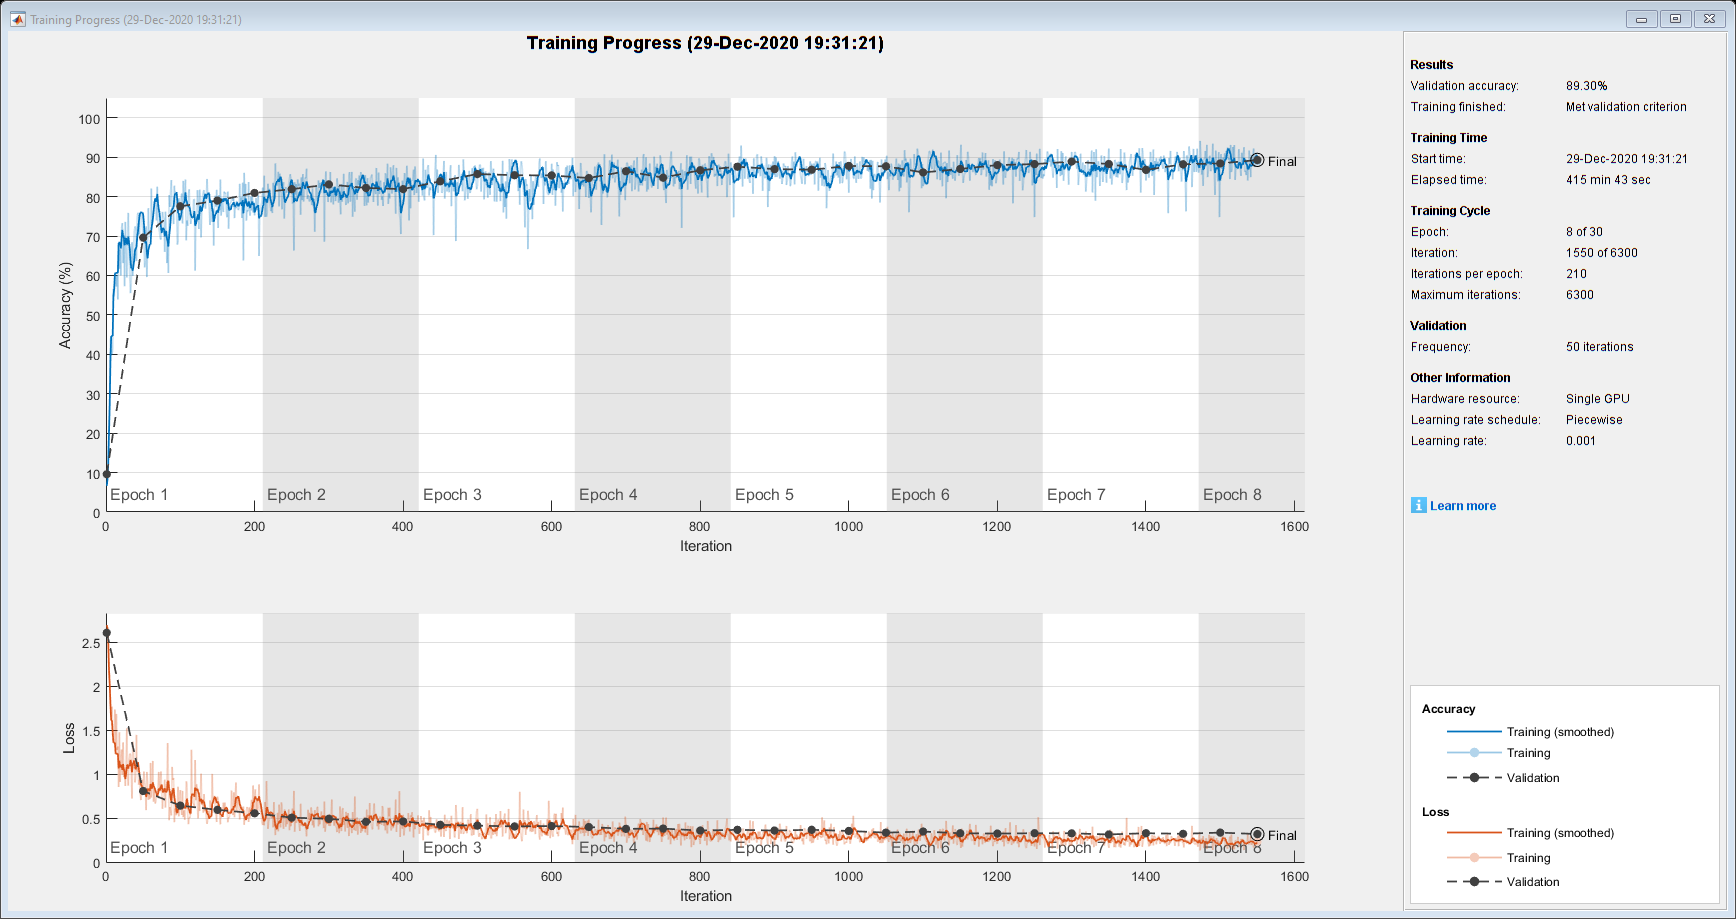

[net, info] = trainNetwork(pximds,lgraph,options);

## Testing on video Stream

video_data = VideoReader('Test_Video.mp4');
depVideoPlayer = vision.DeployableVideoPlayer;

output_file = VideoWriter('output.mp4');

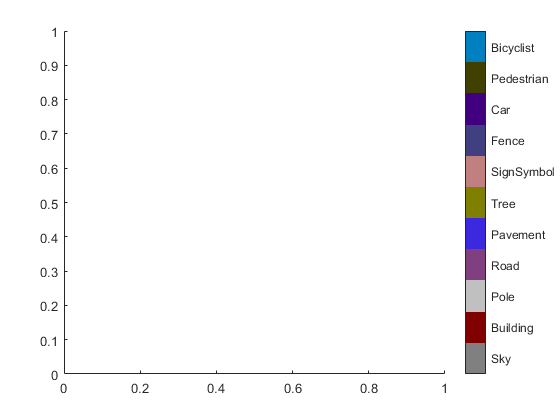

open(output_file);

while hasFrame(video_data)
    
    Frame = readFrame(video_data);
    Frame  = imresize(Frame,imageSize(1:2));
    C = semanticseg(Frame, net);
    B = labeloverlay(Frame,C,'Colormap',cmap,'Transparency',0.4);
    depVideoPlayer(B);
    pixelLabelColorbar(cmap, classes);
    writeVideo(output_file,B);
end

close(output_file);

function labelIDs = camvidPixelLabelIDs()
% Return the label IDs corresponding to each class.
%
% The CamVid dataset has 32 classes. Group them into 11 classes following
% the original SegNet training methodology [1].
%
% The 11 classes are:
%   "Sky" "Building", "Pole", "Road", "Pavement", "Tree", "SignSymbol",
%   "Fence", "Car", "Pedestrian",  and "Bicyclist".
%
% CamVid pixel label IDs are provided as RGB color values. Group them into
% 11 classes and return them as a cell array of M-by-3 matrices. The
% original CamVid class names are listed alongside each RGB value. Note
% that the Other/Void class are excluded below.
labelIDs = { ...
    
    % "Sky"
    [
    128 128 128; ... % "Sky"
    ]
    
    % "Building" 
    [
    000 128 064; ... % "Bridge"
    128 000 000; ... % "Building"
    064 192 000; ... % "Wall"
    064 000 064; ... % "Tunnel"
    192 000 128; ... % "Archway"
    ]
    
    % "Pole"
    [
    192 192 128; ... % "Column_Pole"
    000 000 064; ... % "TrafficCone"
    ]
    
    % Road
    [
    128 064 128; ... % "Road"
    128 000 192; ... % "LaneMkgsDriv"
    192 000 064; ... % "LaneMkgsNonDriv"
    ]
    
    % "Pavement"
    [
    000 000 192; ... % "Sidewalk" 
    064 192 128; ... % "ParkingBlock"
    128 128 192; ... % "RoadShoulder"
    ]
        
    % "Tree"
    [
    128 128 000; ... % "Tree"
    192 192 000; ... % "VegetationMisc"
    ]
    
    % "SignSymbol"
    [
    192 128 128; ... % "SignSymbol"
    128 128 064; ... % "Misc_Text"
    000 064 064; ... % "TrafficLight"
    ]
    
    % "Fence"
    [
    064 064 128; ... % "Fence"
    ]
    
    % "Car"
    [
    064 000 128; ... % "Car"
    064 128 192; ... % "SUVPickupTruck"
    192 128 192; ... % "Truck_Bus"
    192 064 128; ... % "Train"
    128 064 064; ... % "OtherMoving"
    ]
    
    % "Pedestrian"
    [
    064 064 000; ... % "Pedestrian"
    192 128 064; ... % "Child"
    064 000 192; ... % "CartLuggagePram"
    064 128 064; ... % "Animal"
    ]
    
    % "Bicyclist"
    [
    000 128 192; ... % "Bicyclist"
    192 000 192; ... % "MotorcycleScooter"
    ]
    
    };
end
function pixelLabelColorbar(cmap, classNames)
% Add a colorbar to the current axis. The colorbar is formatted
% to display the class names with the color.

colormap(gca,cmap)

% Add colorbar to current figure.
c = colorbar('peer', gca);

% Use class names for tick marks.
c.TickLabels = classNames;
numClasses = size(cmap,1);

% Center tick labels.
c.Ticks = 1/(numClasses*2):1/numClasses:1;

% Remove tick mark.
c.TickLength = 0;
end
function cmap = camvidColorMap()
% Define the colormap used by CamVid dataset.

cmap = [
    128 128 128   % Sky
    128 0 0       % Building
    192 192 192   % Pole
    128 64 128    % Road
    60 40 222     % Pavement
    128 128 0     % Tree
    192 128 128   % SignSymbol
    64 64 128     % Fence
    64 0 128      % Car
    64 64 0       % Pedestrian
    0 128 192     % Bicyclist
    ];

% Normalize between [0 1].
cmap = cmap ./ 255;
end
function [imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionCamVidData(imds,pxds)
% Partition CamVid data by randomly selecting 60% of the data for training. The
% rest is used for testing.
    
% Set initial random state for example reproducibility.
rng(0); 
numFiles = numel(imds.Files);
shuffledIndices = randperm(numFiles);

% Use 60% of the images for training.
numTrain = round(0.60 * numFiles);
trainingIdx = shuffledIndices(1:numTrain);

% Use 20% of the images for validation
numVal = round(0.20 * numFiles);
valIdx = shuffledIndices(numTrain+1:numTrain+numVal);

% Use the rest for testing.
testIdx = shuffledIndices(numTrain+numVal+1:end);

% Create image datastores for training and test.
trainingImages = imds.Files(trainingIdx);
valImages = imds.Files(valIdx);
testImages = imds.Files(testIdx);

imdsTrain = imageDatastore(trainingImages);
imdsVal = imageDatastore(valImages);
imdsTest = imageDatastore(testImages);

% Extract class and label IDs info.
classes = pxds.ClassNames;
labelIDs = camvidPixelLabelIDs();

% Create pixel label datastores for training and test.
trainingLabels = pxds.Files(trainingIdx);
valLabels = pxds.Files(valIdx);
testLabels = pxds.Files(testIdx);

pxdsTrain = pixelLabelDatastore(trainingLabels, classes, labelIDs);
pxdsVal = pixelLabelDatastore(valLabels, classes, labelIDs);
pxdsTest = pixelLabelDatastore(testLabels, classes, labelIDs);
end